# Sea ice classification

We use CICE6 data to objectively classify a number of distinct sea ice regions using an unsupervised method. The benefit of unsupervised classification is that no definition is imposed and clusters are formed through the distribution of the data in *n*-dimensional space. 

## Set up

clear all
clc
close all

addpath functions
%addpath /Users/noahday/GitHub/CICE-analyser/procesvarsing

historydir = '/Volumes/NoahDay5TB/WIM_on/history/fullyears/';

a = dir([historydir '/*.nc']);
n_files = numel(a);

for i = 1:n_files
   filenames(i,:) = strcat(historydir,a(i).name);
   dirdates(i,:) = a(i).name(6:end-3);
end

%var_list = {'aice','hi','hs','fsdrad','sice','iage','vlvl','vrdg'};
    % Static: {'aice','hi','hs','fsdrad','sice','iage','vlvl','vrdg'}
    % Dynamics: {'aice','hi','hs','fsdrad','sice','iage','vlvl','vrdg', 
    %            'uvel','vvel','strength','divu','shear','daidtd','daidtt',
    %            'dagedtd','dagedtt','dafsd_latg','dafsd_latm','dafsd_newi',
    %            'dafsd_weld','dafsd_wave'};
%label_vec = variable_dict(var_list);


## Distribution of each variable

clear Xnan_temp 
load('data/cover_5percent_2015-19.mat')

clear X_out
SIC = 0.15;
[~,wid,dep] = size(data.Xunstandard);
X_temp = data.Xunstandard;%X_raw;

%dep = 365;
%X_temp = data.Xunstandard(:,:,1:dep);
tic
[Xnan,row_idx,Xnew] = clearNaN(X_temp);
toc


disp('Clear NaN done!')

sprintf('The number of NaNs is %g', sum(sum(isnan(Xnan))))
sprintf('The minimum SIC is %g', sum(sum(min(Xnan(:,1)))))


clear Xtemp
close all
conFigure(12,10)
f = figure('Position',[0, 0, 60, 10]);
for i = 1:length(label_vec)
  subplot(2,ceil(length(label_vec)/2),i)
  Xtemp(:,i) = Xnan(:,i);
  hist(Xtemp(:,i),20)
  %hist(Xnan(idx,i),20)
  %xticks(1:length(average_stats(:,i)))
  title(label_vec{i})
end
exportgraphics(f,'figures/distributionVariables_dynamic.pdf','ContentType','vector')


## Optimal number of clusters

clear X_standard_all;
X_standard_all = Xnan;
[~,wid] = size(X_standard_all);

for j = 1:wid-2 % Don't standardise latitude and longitude
    if min(X_standard_all(:,j)) < 0
        % If negatives, then recentre so its all positive
        max_X(j) = max(X_standard_all(:,j));
        min_X(j) = min(X_standard_all(:,j));
        X_standard_all(:,j) = (X_standard_all(:,j) - min_X(j))/(max_X(j) - min_X(j));
    end
    %Step 1: Log transformation as almost all of the data is highly skewed
        X_standard_all(:,j) = log(X_standard_all(:,j)+1);
    %Step 2: Standardization
    % Calculate mean
        mean_X(j) = mean(X_standard_all(:,j));
        % Calculate standard deviation
        std_X(j) = std(X_standard_all(:,j));
        X_standard_all(:,j) = X_standard_all(:,j)/std_X(j);
    % Standardise the data
        max_X(j) = max(X_standard_all(:,j));
        min_X(j) = min(X_standard_all(:,j));
        X_standard_all(:,j) = (X_standard_all(:,j) - min_X(j))/(max_X(j) - min_X(j));
end
disp('Standardisation done!')


% Plotting
eva = evalclusters(X_standard_all(:,1:end-2),'kmeans','CalinskiHarabasz','KList',1:5);
temp = eva.CriterionValues;
conFigure(11)
f = figure;
plot(eva)
ylim([0,1.2*max(eva.CriterionValues)])
exportgraphics(f,'calinskiHarabasz_dynamics.pdf','ContentType','vector')


%% Average stats
clear kmeans_idx
rng(2022)
X = X_standard_all(:,1:end-2);
num_clusters = 3;
tic
[kmeans_idx,C] = kmeans(X,num_clusters,'MaxIter',300);
toc



average_stats = [];
X_temp = [];
X_temp = Xnan;
X_temp = [X_temp, kmeans_idx]; 

%X_temp = [X_temp2(:,[1:3 5:end-2]), kmeans_idx];
clear X_temp2
ylabs = label_vec;
%{"SIC [\%]", "Ice thickness [m]", "Snow thickness [m]", "Mean floe size [m]",  "Bulk ice salinity [ppt]", "Ice age [years]", "Level ice volume", "Ridged ice volume"};

%"Mean floe radius [m]",
for i = 1:num_clusters
    index_class_data = X_temp(:,end) == i;
    class_data = X_temp(index_class_data,1:end-1);
    average_stats(i,:) = mean(class_data);
end

C1 = linspecer(num_clusters);
Cmap = C1([1,3,2],:);%
%%
close all
conFigure(11)
f = figure('Position',[0, 0,40, 40]);% 6, 24]);
label_vec_temp = label_vec;
%label_vec = label_vec([1:3 5:end]);
var_idx = 1:22;%[1,6,2,3,4];%[1,2,5];%

for i = 1:length(var_idx) %1:length(label_vec) % 
  %subplot(2,ceil(length(label_vec(var_idx))/2),i)
  subplot(4,ceil(length(var_idx)/4),i)
  if i == 1
    b = bar(average_stats(:,var_idx(i)).*100, 'facecolor', 'flat');
    b.CData = Cmap;
  else
      b = bar(average_stats(:,var_idx(i)), 'facecolor', 'flat');
      b.CData = Cmap;
  end
  xticks(1:length(average_stats(:,i)))
  %title(label_vec{i})
  ylabel(ylabs(var_idx(i)),'FontSize',14)% ylabs
  %xlabel('Sea ice class','FontSize',14)
  if var_idx(i) == 6
      ylim([0,1])
  elseif var_idx(i) == 3
      ylim([0,0.5])
  elseif var_idx(i) == 4
      ylim([0,850])
  end
end
%sgtitle("\textbf{without floe size}",'FontSize',15)
exportgraphics(f,strcat('stat_comparison_',sprintf('%g',num_clusters),'_with_fsd_dynamic_15_percent_clusters.pdf'),'ContentType','vector')
label_vec = label_vec_temp;

%% Spider plot
% % % Initialize data points
% % P = average_stats(:,1:8);
% % %{'SIC','Ice thick.','Snow thick.','FSD','Salinity'}
% % 
% % 
% % 
% % % Spider plot
% % close all
% % figure
% % spider_plot(P,...
% %     'AxesLabels', label_vec,...
% %     'AxesInterval', 2,...
% %     'FillOption', {'on', 'on','on','on'},...
% %     'FillTransparency', 0.2*ones(1,num_clusters),...
% %     'AxesLimits', [zeros(1,8);1,3,1,850,15,1,1,2]);

%% Spider plot
% Initialize data points
C1 = linspecer(num_clusters);
%Cmap = C1([3,2,1],:);
Cmap = C1([2,1,3],:);


close all
var_vec = [1,2,4,6,8];
label_plot = label_vec;
label_plot{8} = 'Ridged ice';
P = average_stats(:,var_vec);
%{'SIC','Ice thick.','Snow thick.','FSD','Salinity'}
% Spider plot
close all
f = figure;
s = spider_plot_class(P,...
    'AxesLabels', label_plot(var_vec),...
    'FillTransparency', 0.5*ones(1,num_clusters));
% Legend properties
s.LegendLabels = {'Deformed', 'MIZ','Undeformed'};
s.LegendHandle.Location = 'northeastoutside';
s.FillOption = {'on', 'on', 'on'};
s.AxesRadial = 'off';
s.FillTransparency = 0.1;
s.Marker = 'none';
s.Color = Cmap;
s.AxesInterpreter = 'tex';
s.AxesLimits = [0, 0, 0, 0, 0; 1, 2, 850, 1, 1.5];
%addpath /Users/noahday/Documents/MATLAB/matlab2tikz/src/
%matlab2tikz('spider_plot.tex', 'standalone', true);
    %'AxesInterval', 2,...
    %'FillOption', {'on', 'on','on','on'},...
    %,...
    %'AxesLimits', [zeros(1,8);1,3,1,850,15,1,1,2]);
exportgraphics(f,'spider_plot.png','ContentType','image','Resolution',1080)

% Example 1: Minimal number of arguments. All non-specified, optional arguments are set to their default values. Axes labels and limits are automatically generated and set.
% Initialize data points
D1 = [5 3 9 1 2];
D2 = [5 8 7 2 9];
D3 = [8 2 1 4 6];
P = [D1; D2; D3];
% Delete variable in workspace if exists
if exist('s', 'var')
    delete(s);
end
% Spider plot
s = spider_plot_class(P);
% Legend properties
s.LegendLabels = {'D1', 'D2', 'D3'};
s.LegendHandle.Location = 'northeastoutside';

kmeans_cluster.row_idx = row_idx;
kmeans_cluster.label_vec = label_vec;
kmeans_cluster.C = C;
kmeans_cluster.Xnan = Xnan;
kmeans_cluster.X_standard_all = X_standard_all;
kmeans_cluster.num_clusters = num_clusters;
kmeans_cluster.kmeans_idx = kmeans_idx;
kmeans_cluster.var_type = var_type;

save_filename = strcat('kmeans_',var_type,sprintf('%g',num_clusters),'_classes.mat');
save(save_filename,'kmeans_cluster','-v7.3');


load('/Users/noahday/GitHub/sea-ice-classification/kmeans_dynamics3_classes.mat');
row_idx = kmeans_cluster.row_idx;
label_vec = kmeans_cluster.label_vec;
C = kmeans_cluster.C;
Xnan = kmeans_cluster.Xnan;
X_standard_all = kmeans_cluster.X_standard_all;
num_clusters = kmeans_cluster.num_clusters;
kmeans_idx = kmeans_cluster.kmeans_idx;
clear kmeans_cluster

% G-plot matrix
C1 = linspecer(num_clusters);
Cmap = C1([1,3,2],:);
%Cmap = [Cmap, [0.2; 0.2; 0.2]];
font_size = 6;
var_vec = [1,2,4,6,8];
label_plot = label_vec(var_vec);
label_plot = {'SIC [-]', 'Thickness [m]', 'Floe size [m]', 'Age [years]', 'Ridged ice [-]'};
addpath /Users/noahday/GitHub/CICE-plotting-tools/functions/
%conFigure(15)
conFigure(11)
f = figure;
[h,ax] = gplotmatrix(Xnan(1:100:end,var_vec),[],kmeans_idx(1:100:end),Cmap,[],[],false); %['b' 'g' 'r'],[],[],false);
[len, wid] = size(ax);
for i = 1:len
    for j = 1:wid
        ax(i,j).FontSize = font_size;
        ax(i,j).Box = 'on';
        ax(i,j).XTickLabelRotation = 90;
        ax(i,j).YLabel.Rotation = 90;
        ax(i,j).GridAlpha = 0.1;
        ax(i,j).XLabel.Rotation = 45;
        ax(i,j).YLabel.Rotation = 45;
        %ax(i,j) = 0.2;
    end
end

[len, wid, ~] = size(h);
for i = 1:len
    for j = 1:wid
        if i ~= j
            %h(i,j).MarkerFaceAlpha = 0.01;
           % alpha(h(i,j),.5)
           for k = 1:3
                %h(i,j,k).Color = [Cmap(k,:) 0.1];
                h(i,j,k).Color(4)=0.3;
                h(i,j,k).Marker = '.';
                h(i,j,k).MarkerSize = 0.01;
                %h(2,1,1).MarkerFaceColor = "none";
           end
        end
    end
end

%g.XLabel.FontSize = font_size;
set(gca,'FontSize', font_size)
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',font_size)
text([.08 .24 .43 .66 .83], repmat(-.1,1,5), label_plot, 'FontSize',font_size);
text(repmat(-.12,1,5), [.86 .62 .41 .25 .02], label_plot, 'FontSize',font_size, 'Rotation',90);

addpath /Users/noahday/Documents/MATLAB/matlab2tikz/src/
exportgraphics(f,'gplotmatrix.png','ContentType','image','Resolution',1080)
%matlab2tikz('gplotmatrix.tex', 'standalone', true)

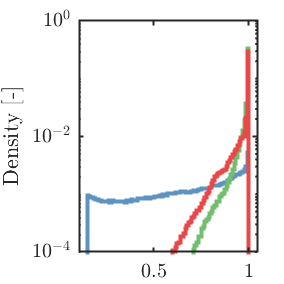

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0 (commit 806c97d99f87f8a1e99a7c54e853c25c82aac301).
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


% Histograms
winter_start = 1826-213; % 1st June
winter_end = 1826-122; % 31 August

summer_start = 1826-364; % 1st Jan
summer_end = 1826-275; % 31 March

C1 = linspecer(num_clusters);
Cmap = C1([1,3,2],:);
%Cmap = [Cmap, [0.2; 0.2; 0.2]];
font_size = 6;
var_vec = [1,2,4];
label_plot = label_vec(var_vec);
label_plot = {'SIC [-]', 'Thickness [m]', 'Floe size [m]'};
addpath /Users/noahday/GitHub/CICE-plotting-tools/functions/
addpath /Users/noahday/Documents/MATLAB/matlab2tikz/src/

clear A
% SIC
row_cumsum = cumsum(row_idx);
X_total = Xnan(row_cumsum(summer_start):end,1);
kmeans_idx_total = kmeans_idx(row_cumsum(summer_start):end);
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;

[counts,centers] = hist(X_total(MIZ_idx,:));
bins = linspace(min(X_total), max(X_total), 100);

A.MIZ = histcounts(X_total(MIZ_idx,:),bins);
A.Old = histcounts(X_total(old_idx,:),bins);
A.Young = histcounts(X_total(young_idx,:),bins);

line_width = 2;
n_points = length(X_total);
close all
conFigure(5,1)
f = figure;
%nhist(A,'noerror')
histogram('BinCounts',A.MIZ./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(1,:),'LineWidth',2)
hold on
histogram('BinCounts',A.Young./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(2,:),'LineWidth',2)
histogram('BinCounts',A.Old./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(3,:),'LineWidth',2)
%xlabel('Sea ice concentration [-]')
ylabel('Density [-]')
set(gca,'YScale','log')
set(gca,'XScale','linear')
ylim([1e-4,1e0])

exportgraphics(f,'kmean_hist_sic_total.pdf','ContentType','vector')
matlab2tikz('kmean_hist_sic_total.tex', 'standalone', true);

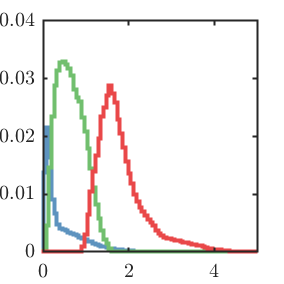

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0 (commit 806c97d99f87f8a1e99a7c54e853c25c82aac301).
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.




% Ice thickness
X_total = Xnan(row_cumsum(summer_start):end,2);
kmeans_idx_total = kmeans_idx(row_cumsum(summer_start):end);
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;

bins = linspace(min(X_total), max(X_total), 100);

A.MIZ = histcounts(X_total(MIZ_idx,:),bins);
A.Old = histcounts(X_total(old_idx,:),bins);
A.Young = histcounts(X_total(young_idx,:),bins);


n_points = length(X_total);
close all

f = figure;
%nhist(A,'noerror')
histogram('BinCounts',A.MIZ./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(1,:),'LineWidth',2)
hold on
histogram('BinCounts',A.Young./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(2,:),'LineWidth',2)
histogram('BinCounts',A.Old./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(3,:),'LineWidth',2)

%ylim([1e-5,1e-1])
xlim([0,5])
%xlabel('Ice thickness [m]')
%set(gca,'Scale','log')
exportgraphics(f,'kmean_hist_itd_total.pdf','ContentType','vector')
matlab2tikz('kmean_hist_itd_total.tex', 'standalone', true);

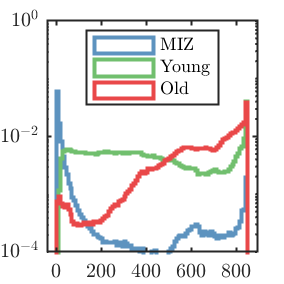

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0 (commit 806c97d99f87f8a1e99a7c54e853c25c82aac301).
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


% Floe size
X_total = Xnan(row_cumsum(summer_start):end,4);
kmeans_idx_total = kmeans_idx(row_cumsum(summer_start):end);
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;

bins = linspace(min(X_total), max(X_total), 100);
A.MIZ = histcounts(X_total(MIZ_idx,:),bins);
A.Old = histcounts(X_total(old_idx,:),bins);
A.Young = histcounts(X_total(young_idx,:),bins);


n_points = length(X_total);
close all

f = figure;
%nhist(A,'noerror')
histogram('BinCounts',A.MIZ./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(1,:),'LineWidth',2)
hold on
histogram('BinCounts',A.Young./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(2,:),'LineWidth',2)
histogram('BinCounts',A.Old./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(3,:),'LineWidth',2)
legend('MIZ','Young','Old','Location','North')
%xlabel('Floe size [m]')
%ylabel('Density [-]')
set(gca,'YScale','log')
set(gca,'XScale','linear')
%ylim([1e-5,1e-1])
ylim([1e-4,1e0])
exportgraphics(f,'kmean_hist_fsd_total.pdf','ContentType','vector')
matlab2tikz('kmean_hist_fsd_total.tex', 'standalone', true);


% SUMMER
% SIC
row_cumsum = cumsum(row_idx);
X_total = Xnan(row_cumsum(summer_start):row_cumsum(summer_end),1);
kmeans_idx_total = kmeans_idx(row_cumsum(summer_start):row_cumsum(summer_end));
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;
bins = linspace(min(X_total), max(X_total), 100);
A.MIZ = histcounts(X_total(MIZ_idx,:),bins);
A.Old = histcounts(X_total(old_idx,:),bins);
A.Young = histcounts(X_total(young_idx,:),bins);


n_points = length(X_total);
close all

f = figure;
%nhist(A,'noerror')
histogram('BinCounts',A.MIZ./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(1,:),'LineWidth',2)
hold on
histogram('BinCounts',A.Young./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(2,:),'LineWidth',2)
histogram('BinCounts',A.Old./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(3,:),'LineWidth',2)

%xlabel('Sea ice concentration [-]')
ylabel('Density [-]')
set(gca,'YScale','log')
set(gca,'XScale','linear')
%ylim([1e-4,1.2*1e-1])
ylim([1e-4,1e0])

exportgraphics(f,'kmean_hist_sic_summer.pdf','ContentType','vector')
matlab2tikz('kmean_hist_sic_summer.tex', 'standalone', true);

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0 (commit 806c97d99f87f8a1e99a7c54e853c25c82aac301).
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


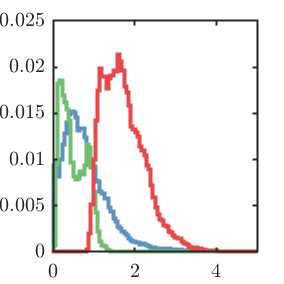

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0 (commit 806c97d99f87f8a1e99a7c54e853c25c82aac301).
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.



% Ice thickness
X_total = Xnan(row_cumsum(summer_start):row_cumsum(summer_end),2);
kmeans_idx_total = kmeans_idx(row_cumsum(summer_start):row_cumsum(summer_end));
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;
bins = linspace(min(X_total), max(X_total), 100);
A.MIZ = histcounts(X_total(MIZ_idx,:),bins);
A.Old = histcounts(X_total(old_idx,:),bins);
A.Young = histcounts(X_total(young_idx,:),bins);


n_points = length(X_total);
close all

f = figure;
%nhist(A,'noerror')
histogram('BinCounts',A.MIZ./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(1,:),'LineWidth',2)
hold on
histogram('BinCounts',A.Young./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(2,:),'LineWidth',2)
histogram('BinCounts',A.Old./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(3,:),'LineWidth',2)

%xlabel('Ice thickness [m]')
%ylabel('Density [-]')
xlim([0,5])
%set(gca,'Scale','log')
exportgraphics(f,'kmean_hist_itd_summer.pdf','ContentType','vector')
matlab2tikz('kmean_hist_itd_summer.tex', 'standalone', true);

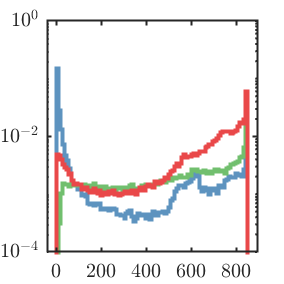

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0 (commit 806c97d99f87f8a1e99a7c54e853c25c82aac301).
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.




% Floe size
X_total = Xnan(row_cumsum(summer_start):row_cumsum(summer_end),4);
kmeans_idx_total = kmeans_idx(row_cumsum(summer_start):row_cumsum(summer_end));
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;
bins = linspace(min(X_total), max(X_total), 100);
A.MIZ = histcounts(X_total(MIZ_idx,:),bins);
A.Old = histcounts(X_total(old_idx,:),bins);
A.Young = histcounts(X_total(young_idx,:),bins);


n_points = length(X_total);
close all

f = figure;
%nhist(A,'noerror')
histogram('BinCounts',A.MIZ./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(1,:),'LineWidth',2)
hold on
histogram('BinCounts',A.Young./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(2,:),'LineWidth',2)
histogram('BinCounts',A.Old./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(3,:),'LineWidth',2)

%xlabel('Floe size [m]')
%ylabel('Density [-]')
set(gca,'YScale','log')
set(gca,'XScale','linear')
%ylim([1e-4,1e-1])
ylim([1e-4,1e0])
exportgraphics(f,'kmean_hist_fsd_summer.pdf','ContentType','vector')
matlab2tikz('kmean_hist_fsd_summer.tex', 'standalone', true);








% WINTER
% SIC
row_cumsum = cumsum(row_idx);
X_total = Xnan(row_cumsum(winter_start):row_cumsum(winter_end),1);
kmeans_idx_total = kmeans_idx(row_cumsum(winter_start):row_cumsum(winter_end));
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;
bins = linspace(min(X_total), max(X_total), 100);
A.MIZ = histcounts(X_total(MIZ_idx,:),bins);
A.Old = histcounts(X_total(old_idx,:),bins);
A.Young = histcounts(X_total(young_idx,:),bins);


n_points = length(X_total);
close all

f = figure;
%nhist(A,'noerror')
histogram('BinCounts',A.MIZ./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(1,:),'LineWidth',2)
hold on
histogram('BinCounts',A.Young./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(2,:),'LineWidth',2)
histogram('BinCounts',A.Old./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(3,:),'LineWidth',2)

xlabel('Ice concentration [-]')
ylabel('Density [-]')
set(gca,'YScale','log')
set(gca,'XScale','linear')
ylim([1e-4,1e0])

exportgraphics(f,'kmean_hist_sic_winter.pdf','ContentType','vector')

matlab2tikz('kmean_hist_sic_winter.tex', 'standalone', true);

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0 (commit 806c97d99f87f8a1e99a7c54e853c25c82aac301).
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.



% Ice thickness
X_total = Xnan(row_cumsum(winter_start):row_cumsum(winter_end),2);
kmeans_idx_total = kmeans_idx(row_cumsum(winter_start):row_cumsum(winter_end));
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;
bins = linspace(min(X_total), max(X_total), 100);
A.MIZ = histcounts(X_total(MIZ_idx,:),bins);
A.Old = histcounts(X_total(old_idx,:),bins);
A.Young = histcounts(X_total(young_idx,:),bins);


n_points = length(X_total);
close all

f = figure;
%nhist(A,'noerror')
histogram('BinCounts',A.MIZ./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(1,:),'LineWidth',2)
hold on
histogram('BinCounts',A.Young./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(2,:),'LineWidth',2)
histogram('BinCounts',A.Old./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(3,:),'LineWidth',2)

xlabel('Ice thickness [m]')
%ylabel('Density [-]')
xlim([0,5])
%set(gca,'Scale','log')
exportgraphics(f,'kmean_hist_itd_winter.pdf','ContentType','vector')
matlab2tikz('kmean_hist_itd_winter.tex', 'standalone', true);

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0 (commit 806c97d99f87f8a1e99a7c54e853c25c82aac301).
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 
 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


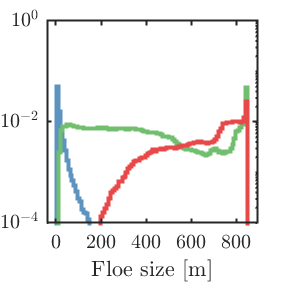

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0 (commit 806c97d99f87f8a1e99a7c54e853c25c82aac301).
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.




% Floe size
X_total = Xnan(row_cumsum(winter_start):row_cumsum(winter_end),4);
kmeans_idx_total = kmeans_idx(row_cumsum(winter_start):row_cumsum(winter_end));
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;
bins = linspace(min(X_total), max(X_total), 100);
A.MIZ = histcounts(X_total(MIZ_idx,:),bins);
A.Old = histcounts(X_total(old_idx,:),bins);
A.Young = histcounts(X_total(young_idx,:),bins);


n_points = length(X_total);
close all

f = figure;
%nhist(A,'noerror')
histogram('BinCounts',A.MIZ./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(1,:),'LineWidth',2)
hold on
histogram('BinCounts',A.Young./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(2,:),'LineWidth',2)
histogram('BinCounts',A.Old./n_points, 'BinEdges', bins,'DisplayStyle','stairs','EdgeColor',Cmap(3,:),'LineWidth',2)

xlabel('Floe size [m]')
%ylabel('Density [-]')
set(gca,'YScale','log')
set(gca,'XScale','linear')
ylim([1e-4,1e0])
exportgraphics(f,'kmean_hist_fsd_winter.pdf','ContentType','vector')
matlab2tikz('kmean_hist_fsd_winter.tex', 'standalone', true);














%clear A
%colormap(["#D95319" "#EDB120" "#0072BD" "#77AC30"])
%temp = reshape(MIZ_width_year(:,summer_days),numel(MIZ_width_year(:,summer_days)),1);
%A.Summer = temp(~isnan(temp));
%temp = reshape(MIZ_width_year(:,autumn_days),numel(MIZ_width_year(:,autumn_days)),1);
%A.Autumn = temp(~isnan(temp));
%temp = reshape(MIZ_width_year(:,winter_days),numel(MIZ_width_year(:,winter_days)),1);
%A.Winter = temp(~isnan(temp));
%temp = reshape(MIZ_width_year(:,spring_days),numel(MIZ_width_year(:,spring_days)),1);
%A.Spring = temp(~isnan(temp));


% 
% close all
% conFigure(11,1)
% f = figure;
% t = tiledlayout(2,1,'TileSpacing','compact')
% nexttile
% nhist(corrected_MIZs_vec(~isnan(corrected_MIZs_vec)))
% xticklabels('')
% set(gca,'YScale','linear')
% nexttile
% nhist(A,'samebins','noerror')
% ylim([0,0.02])
% xlabel('Corrected MIZ width [km]')
% exportgraphics(f,'MIZ_hist.pdf','ContentType','vector')
% %xlim([10,500])
% addpath /Users/noahday/Documents/MATLAB/matlab2tikz/src/
% matlab2tikz('mizwidth_hist_season.tex', 'standalone', true);



% Scatter of variables against each other

row_cumsum = cumsum(row_idx);
clear A
% SIC
X_total = Xnan(row_cumsum(summer_start):end,1);
kmeans_idx_total = kmeans_idx(row_cumsum(summer_start):end);
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;

A.MIZ.SIC = X_total(MIZ_idx,:);
A.Old.SIC = X_total(old_idx,:);
A.Young.SIC = X_total(young_idx,:);

% Thickness
X_total = Xnan(row_cumsum(summer_start):end,2);
kmeans_idx_total = kmeans_idx(row_cumsum(summer_start):end);
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;


A.MIZ.thickness = X_total(MIZ_idx,:);
A.Old.thickness = X_total(old_idx,:);
A.Young.thickness = X_total(young_idx,:);

% Floe size
X_total = Xnan(row_cumsum(summer_start):end,4);
kmeans_idx_total = kmeans_idx(row_cumsum(summer_start):end);
MIZ_idx = kmeans_idx_total == 1;
young_idx = kmeans_idx_total == 2;
old_idx = kmeans_idx_total == 3;

A.MIZ.floesize = X_total(MIZ_idx,:);
A.Old.floesize = X_total(old_idx,:);
A.Young.floesize = X_total(young_idx,:);




rho_sic_thick = corr(A.MIZ.SIC,A.MIZ.thickness, 'type', 'Spearman')

rho_sic_thick = -0.1042

rho_sic_floe = corr(A.MIZ.SIC,A.MIZ.floesize, 'type', 'Spearman')

rho_sic_floe = 0.0099

rho_floe_thick = corr(A.MIZ.floesize,A.MIZ.thickness, 'type', 'Spearman')

rho_floe_thick = 0.0980


rho_sic_thick = corr(A.MIZ.SIC,A.MIZ.thickness)

rho_sic_thick = -0.0310

rho_sic_floe = corr(A.MIZ.SIC,A.MIZ.floesize)

rho_sic_floe = -0.3224

rho_floe_thick = corr(A.MIZ.floesize,A.MIZ.thickness)

rho_floe_thick = 0.1703

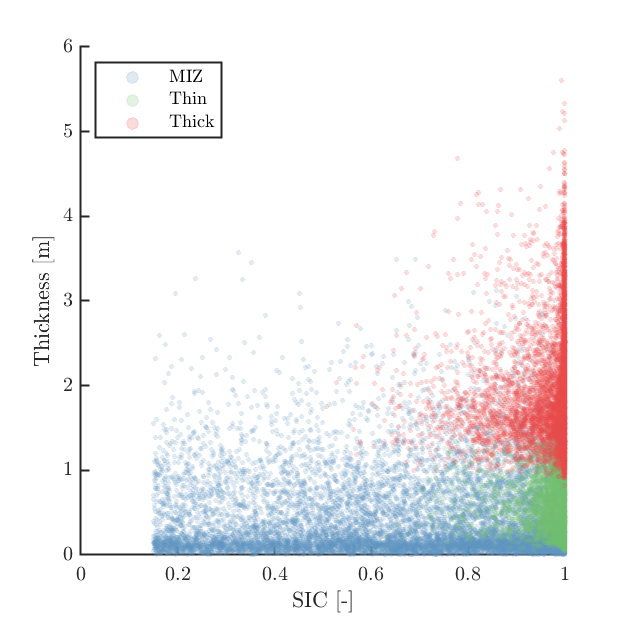


n_points = 10000;
dot_size = 5;

C1 = linspecer(num_clusters);
Cmap = C1([1,3,2],:);

close all
%conFigure(11,1)
clf
conFigure(11,1)
f = figure;
%set(gcf, 'PaperUnits', 'inches');
%set(gcf, 'PaperSize', [4 4]);
%set(gcf, 'PaperPositionMode', 'manual');
%set(gcf, 'PaperPosition', [0 0 4 2]);
%t = tiledlayout(1,3)
%nexttile
scatter(randsample(A.MIZ.SIC,n_points),randsample(A.MIZ.thickness,n_points),dot_size,"MarkerFaceColor",Cmap(1,:),"MarkerEdgeColor",Cmap(1,:))
hold on
scatter(randsample(A.Young.SIC,n_points),randsample(A.Young.thickness,n_points),dot_size,"MarkerFaceColor",Cmap(2,:),"MarkerEdgeColor",Cmap(2,:))
scatter(randsample(A.Old.SIC,n_points),randsample(A.Old.thickness,n_points),dot_size,"MarkerFaceColor",Cmap(3,:),"MarkerEdgeColor",Cmap(3,:))
xlabel('SIC [-]')
ylabel('Thickness [m]')
legend('MIZ','Thin','Thick','Location','NorthWest')
alpha(.2)
saveas(f , 'joint-scatter1.png') 

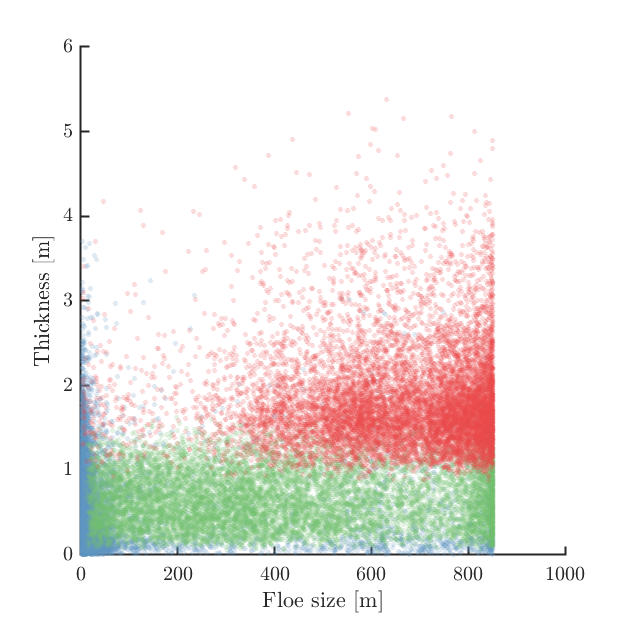

%dim = [.2 .5 .3 .3];
%str = sprintf('Spearman coefficient: %g',rho_sic_thick);
%annotation('textbox',dim,'String',str,'FitBoxToText','on');

%nexttile
conFigure(11,1)
f = figure;
scatter(randsample(A.MIZ.floesize,n_points),randsample(A.MIZ.thickness,n_points),dot_size,"MarkerFaceColor",Cmap(1,:),"MarkerEdgeColor",Cmap(1,:))
hold on
scatter(randsample(A.Young.floesize,n_points),randsample(A.Young.thickness,n_points),dot_size,"MarkerFaceColor",Cmap(2,:),"MarkerEdgeColor",Cmap(2,:))
scatter(randsample(A.Old.floesize,n_points),randsample(A.Old.thickness,n_points),dot_size,"MarkerFaceColor",Cmap(3,:),"MarkerEdgeColor",Cmap(3,:))
alpha(.2)
ylabel('Thickness [m]')
xlabel('Floe size [m]')
%legend('MIZ','Thin','Thick','Location','NorthWest')
saveas(f , 'joint-scatter2.png' ) 

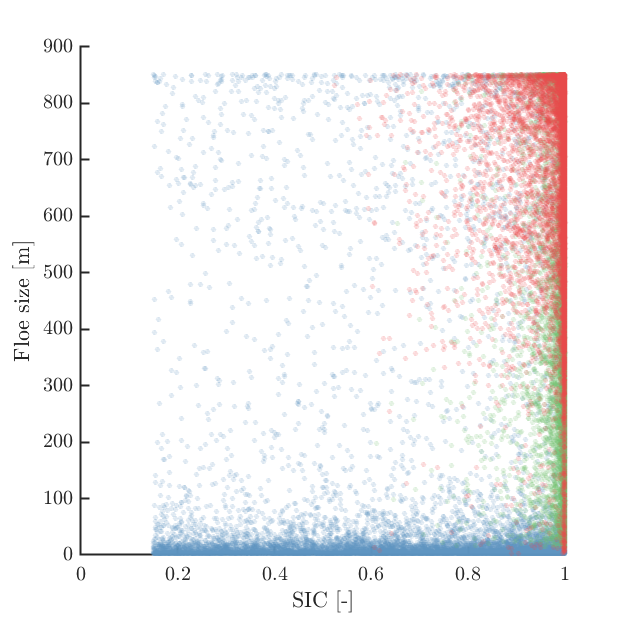

%nexttile
conFigure(11,1)
f = figure;
scatter(randsample(A.MIZ.SIC,n_points),randsample(A.MIZ.floesize,n_points),dot_size,"MarkerFaceColor",Cmap(1,:),"MarkerEdgeColor",Cmap(1,:))
hold on
scatter(randsample(A.Young.SIC,n_points),randsample(A.Young.floesize,n_points),dot_size,"MarkerFaceColor",Cmap(2,:),"MarkerEdgeColor",Cmap(2,:))
scatter(randsample(A.Old.SIC,n_points),randsample(A.Old.floesize,n_points),dot_size,"MarkerFaceColor",Cmap(3,:),"MarkerEdgeColor",Cmap(3,:))
alpha(.2)
xlabel('SIC [-]')
ylabel('Floe size [m]')
%legend('MIZ','Thin','Thick','Location','NorthWest')
saveas(f , 'joint-scatter3.png' ) 


%exportgraphics(f,'joint-scatter.png','ContentType','image')






%% Comparison of MIZ with and without floe size
ylabs = {"SIC [\%]", "Ice thickness [m]", "Snow thickness [m]", "Mean floe size [m]",  "Bulk ice salinity [ppt]", "Ice age [years]", "Level ice volume", "Ridged ice volume"};

% With floe size
average_stats = [];
X_temp = [];
X_temp = Xnan; % 
X_temp = [X_temp, kmeans_idx]; 
index_class_data = X_temp(:,end) == 3;
class_data = X_temp(index_class_data,1:end-1);
average_stats(1,:) = mean(class_data);
clear Xtemp class_data

% Without floe size
X_temp = [];
X_temp = Xnan;
X_temp = [X_temp, kmeans_idx_without_floe]; 
index_class_data = X_temp(:,end) == 3;
class_data = X_temp(index_class_data,1:end-1);
average_stats(2,:) = mean(class_data);
clear Xtemp

%
Cmap_comp = [Cmap(3,:); [141,211,199]./258];
close all
conFigure(11)
f = figure('Position',[0, 0,40, 6]);% 6, 24]);
label_vec_temp = label_vec;
%label_vec = label_vec([1:3 5:end]);
var_idx = [1,6,2,3,4];%[1,2,5];%

for i = 1:length(var_idx) %1:length(label_vec) % 
  %subplot(2,ceil(length(label_vec(var_idx))/2),i)
  subplot(1,length(var_idx),i)
  if i == 1
    b = bar(average_stats(:,var_idx(i)).*100, 'facecolor', 'flat');
    b.CData = Cmap_comp;
  else
      b = bar(average_stats(:,var_idx(i)), 'facecolor', 'flat');
      b.CData = Cmap_comp;
  end
  xticks(1:length(average_stats(:,i)))
  %title(label_vec{i})
  ylabel(ylabs(var_idx(i)),'FontSize',14)% ylabs
  %xlabel('Sea ice class','FontSize',14)
  if var_idx(i) == 6
      ylim([0,1])
  elseif var_idx(i) == 3
      ylim([0,0.5])
  elseif var_idx(i) == 4
      ylim([0,850])
  elseif var_idx(i) == 1
      ylim([0,100])
  elseif var_idx(i) == 2
      ylim([0,1])
  end
  xticklabels(["" ""])
  
end
%sgtitle("\textbf{without floe size}",'FontSize',15)
%exportgraphics(f,strcat('FSD_comparison_',sprintf('%g',num_clusters),'_dynamic_15_percent_clusters.pdf'),'ContentType','vector')
label_vec = label_vec_temp;



## Distribution (histogram) plots

%% Distributions between classifications
count = 1;
nBins = 11;
close all
f = figure('Position',[0, 0, 10, 10]);
for j = [1,4]
     % With floe size

    X_temp = [];
    X_temp = Xnan;
    average_stats = [];
    binEdges = linspace(min(X_temp(:,j)),max(X_temp(:,j)),nBins+1);
   
    X_temp = [X_temp, kmeans_idx];
    
    index_class_data = X_temp(:,end) == 3;
    class_data = X_temp(index_class_data,1:end-1);
    average_stats(1,:) = histcounts(class_data(:,j),binEdges,'Normalization','probability');

    % Without floe size
    X_temp = [];
    X_temp = Xnan;
    X_temp = [X_temp, kmeans_idx_without_floe];
    index_class_data = X_temp(:,end) == 3;
    class_data = X_temp(index_class_data,1:end-1);
    average_stats(2,:) = histcounts(class_data(:,j),binEdges,'Normalization','probability');

    subplot(2,1,count)
    for i = 1:2
      Xtemp(:,i) = Xnan(idx,i);
      histogram('BinEdges',binEdges,'BinCounts',average_stats(i,:),'FaceAlpha',.7,'FaceColor',Cmap_comp(i,:))
      grid on
      hold on
      %hist(Xnan(idx,i),20)
      %xticks(1:length(average_stats(:,i)))
      %title(label_vec{j})
      label_hist(i,:) = num2str(i);
      
    end
    ylabel('Probability')
    ylim([0,1])
    xlabel(ylabs{j})
    %legend(label_hist,'Location','bestoutside')
    count = count + 1;
end
exportgraphics(f,'MIZcompdistribution.pdf','ContentType','vector')

C1 = linspecer(num_clusters);
%Cmap = C1([3,2,1],:);
Cmap = C1([3,2,1],:);
Cmap_comp = Cmap;
line_widths = 40;
close all
f = figure('Position',[0, 0, 60, 10]);
plot(1:5,1:5,'color',Cmap_comp(1,:),'linewidth',line_widths)
hold on
plot(1:5,1:5,'color',Cmap_comp(2,:),'linewidth',line_widths)
legend("MIZ with floe size","MIZ without floe size",'Location','bestoutside','Orientation','vertical','FontSize',20)
exportgraphics(f,strcat('legend_MIZ.pdf'),'ContentType','vector')

%% Distribution of each class

close all

X_temp = [];
[~,~,dep] = size(Xnan);
X_temp = Xnan;
X_temp = [X_temp(:,1:end-2), kmeans_idx];
nBins = 10;

conFigure(12,3)
clear label_hist
f = figure%('Position',[0, 0, 30, 10]);
count = 1;
for j = [1,4]
    average_stats = [];
    binEdges = linspace(min(X_temp(:,j)),max(X_temp(:,j)),nBins+1);
    for i = 1:num_clusters
        index_class_data = X_temp(:,end) == i;
        class_data = X_temp(index_class_data,1:end-1);
        average_stats(i,:) = histcounts(class_data(:,j),binEdges,'Normalization','probability');
    end
    %subplot(2,ceil(length(label_vec)/2),j)
    subplot(1,2,count)
    for i = num_clusters:-1:1
      Xtemp(:,i) = Xnan(idx,i);
      histogram('BinEdges',binEdges,'BinCounts',average_stats(i,:),'FaceAlpha',.7,'FaceColor',Cmap(i,:))
      hold on
      %hist(Xnan(idx,i),20)
      %xticks(1:length(average_stats(:,i)))
      %title(label_vec{j})
      label_hist(i,:) = num2str(i);
      
    end
    ylabel('Probability')
    ylim([0,1])
    xlabel(ylabs{j})
    %legend(label_hist,'Location','bestoutside')
    count = count + 1;
end

exportgraphics(f,'distributionClassVariables.pdf','ContentType','vector')




## Maps

close all
SIC = 0.15;
pram.ice_edge_color = 0.7*[0.4660 0.6740 0.1880];
line_width = 1;

addpath functions
[lat,lon,~,ulat,ulon] = grid_read('om2');
clear X_map MIZ_width
% Make worldmap with colour matching
hdd = "on";

if hdd == "on"
    uarea = data_format(filenames(1,:),"uarea");
end

[num_files,~] = size(filenames);
sector = "SH";
coords = sector_coords(sector);
font_size = 7;
plot_type = "kmeans";
plotting = "on";
conFigure(11)
X_new = Xnan;

[len,wid] = size(lat);
file_number = 1826-31+1-30-31-30;%31 + 28 + 31 + 30 + 31 + 30 + 31 + 31 + 30 + 31 + 30 + 31 + 1;


row_file = [0,cumsum(row_idx)];
row_vec = row_file(file_number)+1:row_file(file_number+1);
%temp_idx = kmeans_idx_without_floe;
temp_idx = kmeans_idx;
file_idx = temp_idx(row_vec);
file_idx = reshape(file_idx,length(file_idx),1);
if hdd == "on"
    [aice, sector_mask] = data_format_sector(filenames(file_number,:),'aice',sector);
end
X_map = [file_idx, X_new(row_vec,end-1:end)];
k_means = NaN.*ones(len,wid);
for i = 1:length(file_idx)
    [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
    k_means(lon_pos,lat_pos) = file_idx(i); 
    k_means(~sector_mask) = NaN;
end
if hdd == "on"
    ice_mask =  aice > 0.15;
     [lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice,0.15,sector,lat,lon);
end
if plotting == "on"
    f = figure;
    set(gcf,'Visible', 'on')
    w = worldmap('world');
        axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
        setm(w, 'Origin', [-90 0 0]);
        setm(w, 'maplatlimit', [-90,-53]);
        setm(w, 'grid', 'off');
        setm(w, 'frame', 'off');
        %setm(w, 'MLineLimit',[-60,-75]);
        %setm(w,'MLineException',[-90 0 90 180])
        setm(w, "FontColor",[0.5, 0.5, 0.5])
        setm(w, 'labelrotation', 'on')
        setm(w, 'meridianlabel', 'on','FontSize',font_size)
        setm(w, 'parallellabel', 'off','FontSize',font_size)
        setm(w, 'mlabellocation', 60);
        setm(w, 'plabellocation', 5);
        pcolorm(lat,lon,k_means,'FaceAlpha',0.99)
        land = shaperead('landareas', 'UseGeoCoords', true);
        geoshow(w, land, 'FaceColor', [0.5 0.5 0.5],'FaceAlpha',.5)
        colorbar; %cmocean('deep');
        %colormap(Cmap)
        %cb = colorbar;
        title(dirdates(file_number,:),'Color','black','FontSize',font_size+3)
        %plotm(lat_ice_edge(1:end-2),lon_ice_edge(1:end-2),'color','#7A7A7A','LineWidth',0.5,'LineStyle','-')
        %textm(lat_ice_edge(190)+2, lon_ice_edge(190),'15\% ice edge', 'FontSize', font_size, 'Color','#7A7A7A')
        scalebar('length',1000,...
            'units','km',...
            'color','k','location','sw',...
            'fontangle','italic','FontSize',font_size)
        if plot_type == "pc1"
            caxis([0,1])
        elseif plot_type == "kmeans"
            %cb = colorbar; cmocean('deep',num_clusters)
            %cb.TickLabels = region_label; 
            %cb.Ticks = 1:num_clusters;
            %cb.Location = 'southoutside';%cb.Location = 'northoutside';
            %cb.Location = 'eastoutside';
            %caxis([0.5,num_clusters+0.5])
            %cb.AxisLocation = 'out';
            %cb.FontSize = font_size+3;
        end
end
savefilename = strcat(sprintf('%g',num_clusters),'cluster_',var_type,'_',dirdates(file_number,:),'.pdf');
exportgraphics(f,savefilename,'ContentType','vector')
clear X_map X_temp sb




## Movies

addpath functions
%% MOVIES
clear area_region MIZ_width MIZ_width_corrected X_map
SIC = 0.15;
pram.ice_edge_color = 0.7*[0.4660 0.6740 0.1880];
line_width = 1;

addpath functions
[lat,lon,~,ulat,ulon] = grid_read('om2');

% Make worldmap with colour matching
uarea = data_format(filenames(1,:),"uarea");

[num_files,~] = size(filenames);
sector = "SH";
coords = sector_coords(sector);
font_size = 5;
plot_type = "kmeans";
plotting = "off";
conFigure(11)
X_new = Xnan(:,:);
[len,wid] = size(lat);


file_number_vec = 1826-365:1:1826;
for file_number = file_number_vec 
    row_file = [0,cumsum(row_idx)];
    row_vec = row_file(file_number)+1:row_file(file_number+1);
    temp_idx = kmeans_idx;
    file_idx = temp_idx(row_vec);
    file_idx = reshape(file_idx,length(file_idx),1);

    [aice, sector_mask] = data_format_sector(filenames(file_number,:),'aice',sector);
    %[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice,SIC,sector,lat,lon);
    X_map = [file_idx, X_new(row_vec,end-1:end)];%[file_idx, X_new(:,end-1:end)];%
    k_means = NaN.*ones(len,wid);
    for i = 1:length(file_idx)
        [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
        k_means(lon_pos,lat_pos) = file_idx(i); 
        k_means(~sector_mask) = NaN;
    end
    
    ice_mask =  aice > 0.01;
   % k_means(~ice_mask) = NaN;
    if plotting == "on"
        f = figure;
        set(gcf,'Visible', 'off')
        w = worldmap('world');
            %axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            %setm(w, 'Origin', [-90 0 0]);
            %setm(w, 'maplatlimit', [-90,-50]);
            
            %setm(w, 'maplonlimit', [coords(1,2),coords(3,2)]);
            if sector == "EA"
                axesm eqdcylin; 
                setm(w, 'Origin', [0 28 0]); 
                setm(w, 'maplatlimit', [-75,-50]); setm(w, 'maplonlimit', [1,150]); 
                setm(w, 'meridianlabel', 'on'); setm(w, 'parallellabel', 'on'); 
                setm(w, 'mlabellocation', 30); setm(w, 'plabellocation', 10); 
                setm(w, 'mlabelparallel', 'south','FontColor','black','FontSize',3);
                setm(w, 'grid', 'off');
                setm(w, 'labelrotation', 'on')
            else
                axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
                setm(w, 'Origin', [-90 0 0]);
                setm(w, 'maplatlimit', [-90,-50]);
                setm(w, 'grid', 'off');
                setm(w, 'labelrotation', 'on')
            end
            pcolorm(lat,lon,k_means)
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.5 0.5])
            %colorbar; %cmocean('deep');
            colormap(Cmap)
            cb = colorbar;
            title(dirdates(file_number,:),'Color','black','FontSize',font_size+5)
            %plotm(lat_ice_edge,lon_ice_edge,'-','color',pram.ice_edge_color,'LineWidth',line_width)

            %cb = colorbar; cmocean('deep',num_clusters)
            %cb.TickLabels = region_label; 
            cb.Ticks = 1:num_clusters;
            %cb.Location = 'southoutside';%cb.Location = 'northoutside';
            cb.Location = 'eastoutside';
            caxis([1,num_clusters])
            cb.AxisLocation = 'in';

    end
    % Calculate the width of the MIZ
    % CHECK WHAT number MIZ is !!!!!!!!
    miz_def = 1;
    [MIZ_width(file_number,:),MIZ_width_corrected(file_number,:), miz_class, MIZ_zone] = calculate_miz_width(convertStringsToChars(filenames(file_number,:)),sector,k_means,miz_def); % Number corresponding to MIZ at end
   


    % Calculate the perimeter and area of the zones
    for rgn_number = 1:num_clusters
        region_data = k_means == rgn_number;
        [len, wid] = size(k_means);
        perimeter_region(rgn_number,file_number) = find_perimeter(region_data,len,wid);

        % Area
        area_region(rgn_number, file_number) = sum(sum(uarea.*region_data));
    end
    if plotting == "on"
        if file_number == file_number_vec(1)
            %gif('kmeans_SH_SA_05_stndzd__dynamic3class2019.gif','DelayTime',0.5,'resolution',500,'overwrite',true)
            gif('temp.gif','DelayTime',0.5,'resolution',500,'overwrite',true)
        else
            gif
        end
    end
    k_means_map(:,:,file_number) = k_means;
    % Clear the excess
    clear aice ice_mask k_means file_idx X_map
end



%file_number_vec 

figure
plot(MIZ_width(file_number_vec(end-5),:))

figure
plot(datetime(dirdates(file_number_vec,:)),mean(MIZ_width(file_number_vec,:)'))
ylim([0,400])

ts_dates = datenum(dirdates(file_number_vec,:));

f = figure('Position',[0, 0, 30, 10]);
conFigure(14,3)
%yyaxis left;
boxplot(MIZ_width(file_number_vec,:)','position',ts_dates,'PlotStyle','compact')
%ylim([0,1600])
hold on
%yyaxis right;
plot(ts_dates,mean(MIZ_width(file_number_vec,:)'),'color',[0.8500 0.3250 0.0980])
plot(ts_dates,nanmean(MIZ_width_corrected(file_number_vec,:)'),'color',[0.9290 0.6940 0.1250])
plot(ts_dates([6,15,27,36]),[40,150,200,60],'pentagram','color',[0.4660 0.6740 0.1880],'markersize',10,"MarkerFaceColor",[1 1 0])
plot(ts_dates([6,15,27,36]),[50,190,230,75],'pentagram','color',[0.4940 0.1840 0.5560],'markersize',10,"MarkerFaceColor",[1 1 0])
legend('Mean MIZ width','Mean MIZ width corrected','Brouwer et al. (2022) linear','Brouwer (2022) exponential','Location','north')
ylabel('MIZ width [km]')
%ylim([0,1600])
%Fix ticks
ax=gca;
ax.XTick = ts_dates
ax.XTickLabels = cellstr(dirdates(file_number_vec,:));
exportgraphics(f,'boxplot.pdf','ContentType','vector')



MIZ_width_mean = mean(MIZ_width(file_number_vec,:)');
MIZ_width_sd = std(MIZ_width(file_number_vec,:)');

ts_dates_CI  = [ts_dates', fliplr(ts_dates')];
MIZ_width_CI = [MIZ_width_mean-MIZ_width_sd, fliplr(MIZ_width_mean+MIZ_width_sd)];

corrected_MIZ_width_sd = nanstd(MIZ_width_corrected(file_number_vec,:)');
corrected_MIZ_width_mean = nanmean(MIZ_width_corrected(file_number_vec,:)');
MIZ_width_corrected_CI = [corrected_MIZ_width_mean-corrected_MIZ_width_sd, fliplr(corrected_MIZ_width_mean+corrected_MIZ_width_sd)];

MIZ_width_median = nanmedian(MIZ_width(file_number_vec,:)');
MIZ_width_median_corrected = nanmedian(MIZ_width_corrected(file_number_vec,:)');
font_size = 12;

f = figure('Position',[0, 0, 30, 10]);
conFigure(12,3)
set(gca,'FontSize',18) 
%yyaxis left;
%boxplot(MIZ_width(file_number_vec,:)','position',ts_dates,'PlotStyle','compact')
%ylim([0,1600])
brouwer_color = [0.4660 0.6740 0.1880];
MIZ_color = [217,95,14]./256; %[0.9290 0.6940 0.1250];
%yyaxis right;
%plot(ts_dates,mean(MIZ_width(file_number_vec,:)'),'color',[0.8500 0.3250 0.0980])
hold on
brouwer_dates = [6,15,27,36];
brouwer_val = [40,150,200,60];
lower_IQR = [20 50 70 30];
upper_IQR = [50 50 70 70];
for i = 1:length([6,15,27,36])
    %stem(ts_dates(brouwer_dates(i)),brouwer_val(i)+20,'BaseValue',brouwer_val(i));
    quiver(ts_dates(brouwer_dates(i)),brouwer_val(i)-lower_IQR(i),0,lower_IQR(i),0,'marker',"_","ShowArrowHead","off",'color',brouwer_color,'HandleVisibility','off')
    quiver(ts_dates(brouwer_dates(i)),brouwer_val(i)+upper_IQR(i),0,-upper_IQR(i),0,'marker',"_","ShowArrowHead","off",'color',brouwer_color,'HandleVisibility','off')
end
plot(ts_dates,nanmean(MIZ_width_corrected(file_number_vec,:)'),'color',MIZ_color,'linewidth',2)
plot(ts_dates([6,15,27,36]),[40,150,200,60],'s','color',[0.4660 0.6740 0.1880],'markersize',10,"MarkerFaceColor",brouwer_color)
%plot(ts_dates([6,15,27,36]),[50,190,230,75],'pentagram','color',[0.4940 0.1840 0.5560],'markersize',10,"MarkerFaceColor",[1 1 0])
%plot(ts_dates,MIZ_width_median,'color','blue')
%plot(ts_dates,MIZ_width_median_corrected,'color','red')
%legend('Mean MIZ width','Mean MIZ width corrected','Brouwer et al. (2022) linear','Brouwer (2022) exponential','Location','northoutside','Orientation','horizontal')
fill(ts_dates_CI, MIZ_width_corrected_CI , 1,....
        'facecolor',MIZ_color, ...
        'edgecolor','none', ...
        'facealpha', 0.2);

legend('Unsupervised MIZ','Brouwer et al. (2022)','','Location','northwest','Orientation','vertical')
ylabel('Corrected MIZ width [km]')

%fill(ts_dates_CI, MIZ_width_CI , 1,....
%        'facecolor',[0.8500 0.3250 0.0980], ...
%        'edgecolor','none', ...
%        'facealpha', 0.1);


ylim([0,300])
%Fix ticks
xlim([ts_dates(1),ts_dates(end)])
%xlabel('Months of 2019')
ax=gca;
ts_dates_months = cumsum([ts_dates(1), 31, 28, 31, 30, 31, 30, 31, 31, 30, 31, 30, 31]);
ax.XTick = ts_dates_months;
%ax.XTickLabels = {'J','F','M','A','M','J','J','A','S','O','N','D'};%cellstr(dirdates(cumsum([1826-365, 31, 28, 31, 30, 31, 30, 31, 31, 30, 31, 30, 31]),:));
ax.XTickLabels = cellstr(datetime(dirdates(cumsum([1826-365, 31, 28, 31, 30, 31, 30, 31, 31, 30, 31, 30, 31]),:),"Format","MMM")+1);
exportgraphics(f,'ts_mizwidth.pdf','ContentType','vector')
%addpath /Users/noahday/Documents/MATLAB/matlab2tikz/src/
%matlab2tikz('miz_comp_brouwer.tex', 'standalone', true);


%ax.XTick=ax.XTick(1:12:end)
%Set xtickformat -- read more about possible formats: 
%https://se.mathworks.com/help/matlab/ref/datestr.html
%datetick('x','mm','keepticks');

corrected_MIZs = MIZ_width_corrected(file_number_vec,:)';
corrected_MIZs_vec = reshape(corrected_MIZs,numel(corrected_MIZs),1);
[N,edges] = histcounts(corrected_MIZs_vec);
conFigure(11,3)
f = figure;
histogram(corrected_MIZs_vec)
ylabel('Frequency')
xlabel('Corrected MIZ width [km]')
xlim([0,450])
exportgraphics(f,'mizwidth_hist.pdf','ContentType','vector')
matlab2tikz('mizwidth_hist.tex', 'standalone', true);



% Make scatter of MIZ with colored dots for each sector



% Get some random data
x       = linspace(0.3, pi-0.3, 10);
Data    = sin(x) + randn(1, 10)/10;
Data_sd = 0.1+randn(1,10)/30;

% prepare it for the fill function
figure
x_ax    = 1:10;
X_plot  = [x_ax, fliplr(x_ax)];
Y_plot  = [Data-1.96.*Data_sd, fliplr(Data+1.96.*Data_sd)];

% plot a line + confidence bands
hold on 
plot(x_ax, Data, 'blue', 'LineWidth', 1.2)
fill(X_plot, Y_plot , 1,....
        'facecolor','blue', ...
        'edgecolor','none', ...
        'facealpha', 0.3);
hold off 


 %[MIZ_width(file_number,:), miz_class, MIZ_zone] = calculate_effective_miz_width(convertStringsToChars(filenames(file_number,:)),sector,k_means,1); % Number corresponding to MIZ at end
   figure
   plot(lon(1:361,1),MIZ_width)
   hold on
   plot(lon(1:360,1),MIZ_width_corrected)
   legend('MIZ width [km]', 'MIZ width corrected [km]')


p1 = [2 3];                         % First Point
p2 = [9 8];                         % Second Point
dp = p2-p1;                         % Difference
figure
quiver(p1(1),p1(2),dp(1),dp(2),0,'marker',"_")
grid
axis([0  10    0  10])
text(p1(1),p1(2), sprintf('(%.0f,%.0f)',p1))
text(p2(1),p2(2), sprintf('(%.0f,%.0f)',p2))



% Confusion matrix comparing 
load('data/kmeans_map_3_cover_clusters_2015_2019.mat')
% Reads in as "kmean_map" structure
data_cover = kmean_map.data;
data_dynamics = k_means_map;

filenumber = 20;

data_cover_vec = reshape(data_cover(:,:,file_number_vec(filenumber)),[numel(data_cover(:,:,file_number_vec(filenumber))),1]);
% Change 3 to 1 then 2 to 3
idx1 = data_cover_vec == 1;
idx2 = data_cover_vec == 2;
idx3 = data_cover_vec == 3;
data_cover_vec(idx3) = 1;
data_cover_vec(idx1) = 2;
data_cover_vec(idx2) = 3;

data_dynamics_vec = reshape(data_dynamics(:,:,file_number_vec(filenumber)),[numel(data_dynamics(:,:,file_number_vec(filenumber))),1]);
C = confusionmat(data_cover_vec,data_dynamics_vec);

f = figure;
confusionchart(C)
xlabel('Classes with dynamic variables')
ylabel('Classes with static variables')
exportgraphics(f,'confmatrix.pdf','ContentType','vector')

f = figure;
        set(gcf,'Visible', 'off')
        w = worldmap('world');
            %axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            %setm(w, 'Origin', [-90 0 0]);
            %setm(w, 'maplatlimit', [-90,-50]);
            
            %setm(w, 'maplonlimit', [coords(1,2),coords(3,2)]);
            pcolorm(lat,lon,k_means)
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.5 0.5])

## Plot any variable on map

addpath functions
%% MOVIES
clear area_region MIZ_width MIZ_width_corrected X_map
SIC = 0.15;
pram.ice_edge_color = 0.7*[0.4660 0.6740 0.1880];
line_width = 1;

addpath functions
[lat,lon,~,ulat,ulon] = grid_read('om2');

% Make worldmap with colour matching
uarea = data_format(filenames(1,:),"uarea");

[num_files,~] = size(filenames);
sector = "SH";
coords = sector_coords(sector);
font_size = 5;
plot_type = "kmeans";
plotting = "off";
conFigure(11)
X_new = Xnan(:,:);
[len,wid] = size(lat);


file_number_vec = 1826-365:180:1826;
for file_number = file_number_vec 
    row_file = [0,cumsum(row_idx)];
    row_vec = row_file(file_number)+1:row_file(file_number+1);
    temp_idx = kmeans_idx;
    file_idx = temp_idx(row_vec);
    file_idx = reshape(file_idx,length(file_idx),1);

    [aice, sector_mask] = data_format_sector(filenames(file_number,:),'aice',sector);
    %[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice,SIC,sector,lat,lon);
    X_map = [file_idx, X_new(row_vec,end-1:end)];%[file_idx, X_new(:,end-1:end)];%
    k_means = NaN.*ones(len,wid);
    for i = 1:length(file_idx)
        [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
        k_means(lon_pos,lat_pos) = file_idx(i); 
        k_means(~sector_mask) = NaN;
    end
    
    ice_mask =  aice > 0.15;
   % k_means(~ice_mask) = NaN;
    if plotting == "on"
        f = figure;
        set(gcf,'Visible', 'off')
        w = worldmap('world');
            %axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            %setm(w, 'Origin', [-90 0 0]);
            %setm(w, 'maplatlimit', [-90,-50]);
            
            %setm(w, 'maplonlimit', [coords(1,2),coords(3,2)]);
            if sector == "EA"
                axesm eqdcylin; 
                setm(w, 'Origin', [0 28 0]); 
                setm(w, 'maplatlimit', [-75,-50]); setm(w, 'maplonlimit', [1,150]); 
                setm(w, 'meridianlabel', 'on'); setm(w, 'parallellabel', 'on'); 
                setm(w, 'mlabellocation', 30); setm(w, 'plabellocation', 10); 
                setm(w, 'mlabelparallel', 'south','FontColor','black','FontSize',3);
                setm(w, 'grid', 'off');
                setm(w, 'labelrotation', 'on')
            else
                axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
                setm(w, 'Origin', [-90 0 0]);
                setm(w, 'maplatlimit', [-90,-50]);
                setm(w, 'grid', 'off');
                setm(w, 'labelrotation', 'on')
            end
            pcolorm(lat,lon,k_means)
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.5 0.5])
            %colorbar; %cmocean('deep');
            colormap(Cmap)
            cb = colorbar;
            title(dirdates(file_number,:),'Color','black','FontSize',font_size+5)
            %plotm(lat_ice_edge,lon_ice_edge,'-','color',pram.ice_edge_color,'LineWidth',line_width)

            %cb = colorbar; cmocean('deep',num_clusters)
            %cb.TickLabels = region_label; 
            cb.Ticks = 1:num_clusters;
            %cb.Location = 'southoutside';%cb.Location = 'northoutside';
            cb.Location = 'eastoutside';
            caxis([1,num_clusters])
            cb.AxisLocation = 'in';

            %[ice_u, sector_mask] = data_format_sector(filenames(file_number,:),'uvel',sector);
            %[ice_v, sector_mask] = data_format_sector(filenames(file_number,:),'vvel',sector);
            % qv = quivermc(ulat,ulon,ice_u,ice_v,'density',15,'units','Ice speed [m/s]','reference',0.3,'color',[0,0,0],'FontSize',1);

    end
    % Calculate the width of the MIZ
    % CHECK WHAT number MIZ is !!!!!!!!
    miz_def = 1;
    [MIZ_width(file_number,:),MIZ_width_corrected(file_number,:), miz_class, MIZ_zone] = calculate_miz_width(convertStringsToChars(filenames(file_number,:)),sector,k_means,miz_def); % Number corresponding to MIZ at end
   


    % Calculate the perimeter and area of the zones
    for rgn_number = 1:num_clusters
        region_data = k_means == rgn_number;
        [len, wid] = size(k_means);
        perimeter_region(rgn_number,file_number) = find_perimeter(region_data,len,wid);

        % Area
        area_region(rgn_number, file_number) = sum(sum(uarea.*region_data));
    end
    if plotting == "on"
        if file_number == file_number_vec(1)
            %gif('kmeans_SH_SA_05_stndzd__dynamic3class2019.gif','DelayTime',0.5,'resolution',500,'overwrite',true)
            gif('temp.gif','DelayTime',0.5,'resolution',500,'overwrite',true)
        else
            gif
        end
    end
    k_means_map(:,:,file_number) = k_means;
    % Clear the excess
    disp(file_number)
    clear aice ice_mask k_means file_idx X_map
end



## Plot time series of each variable in each class


addpath functions
%% MOVIES
clear area_region MIZ_width MIZ_width_corrected X_map
SIC = 0.15;
pram.ice_edge_color = 0.7*[0.4660 0.6740 0.1880];
line_width = 1;

addpath functions
[lat,lon,~,ulat,ulon] = grid_read('om2');

% Make worldmap with colour matching
uarea = data_format(filenames(1,:),"uarea");

[num_files,~] = size(filenames);
sector = "SH";
coords = sector_coords(sector);
font_size = 5;
%for var_idx = 1:22
var_idx = 5;
var_name = var_list{var_idx};
var_name = "hi";
plotting = "off";

    conFigure(11)
    X_new = Xnan(:,:);
    [len,wid] = size(lat);
    
    
    file_number_vec = 1826-365:20:1826;
    for file_number = file_number_vec 
        row_file = [0,cumsum(row_idx)];
        row_vec = row_file(file_number)+1:row_file(file_number+1);
        temp_idx = kmeans_idx;
        file_idx = temp_idx(row_vec);
        file_idx = reshape(file_idx,length(file_idx),1);
    
        [aice, sector_mask] = data_format_sector(filenames(file_number,:),'aice',sector);
        %[lat_ice_edge, lon_ice_edge, edge] = find_ice_edge(aice,SIC,sector,lat,lon);
        X_map = [file_idx, X_new(row_vec,end-1:end)];%[file_idx, X_new(:,end-1:end)];%
        k_means = NaN.*ones(len,wid);
        %var_data = NaN.*ones(len,wid);
        for i = 1:length(file_idx)
            [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
            k_means(lon_pos,lat_pos) = file_idx(i); 
            %var_data(lon_pos,lat_pos) = X_new(i,var_idx);     
        end
        k_means(~sector_mask) = NaN;
        %var_data(~sector_mask) = NaN;
        if var_idx > 17 % DAFSD variables
            temp_data = data_format_sector(filenames(file_number,:), var_name,sector);
            NFSD = ncread(filenames(file_number,:),'NFSD');
            [floe_binwidth, floe_rad_l, floe_rad_h, floe_area_binwidth] = cice_parameters(NFSD);
            var_data = zeros(size(aice));
            for nf = 1:numel(NFSD)
                var_data = var_data + temp_data(:,:,nf).*floe_binwidth(nf);
            end
        elseif var_name == "dafsd_wave"
            temp_data = data_format_sector(filenames(file_number,:), var_name,sector);
            var_data = squeeze(temp_data(:,:,12));
        elseif var_name == "dafsd_wave_vec"
            temp_data = data_format_sector(filenames(file_number,:), "dafsd_wave",sector);
            var_data = temp_data; %squeeze(temp_data(:,:,12));
        else
            var_data = data_format_sector(filenames(file_number,:),var_name,sector);
        end
        ice_mask =  aice > 0.15;
        var_data(~ice_mask) = NaN;
    
      if plotting == "on"
        f = figure;
        set(gcf,'Visible', 'off')
        w = worldmap('world');
            %axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            %setm(w, 'Origin', [-90 0 0]);
            %setm(w, 'maplatlimit', [-90,-50]);
            
            %setm(w, 'maplonlimit', [coords(1,2),coords(3,2)]);
            if sector == "EA"
                axesm eqdcylin; 
                setm(w, 'Origin', [0 28 0]); 
                setm(w, 'maplatlimit', [-75,-50]); setm(w, 'maplonlimit', [1,150]); 
                setm(w, 'meridianlabel', 'on'); setm(w, 'parallellabel', 'on'); 
                setm(w, 'mlabellocation', 30); setm(w, 'plabellocation', 10); 
                setm(w, 'mlabelparallel', 'south','FontColor','black','FontSize',3);
                setm(w, 'grid', 'off');
                setm(w, 'labelrotation', 'on')
            else
                axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
                setm(w, 'Origin', [-90 0 0]);
                setm(w, 'maplatlimit', [-90,-50]);
                setm(w, 'grid', 'off');
                setm(w, 'labelrotation', 'on')
            end
            pcolorm(lat,lon,var_data)
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.5 0.5])
            caxis([-50,50])
            cmocean('balance','pivot',0)
            cb = colorbar;
            title(dirdates(file_number,:),'Color','black','FontSize',font_size+5)
     
            cb.Location = 'eastoutside';
            
            cb.AxisLocation = 'in';
            if plotting == "on"
        if file_number == file_number_vec(1)
                %gif('kmeans_SH_SA_05_stndzd__dynamic3class2019.gif','DelayTime',0.5,'resolution',500,'overwrite',true)
                gif(strcat(var_list{var_idx},'.gif'),'DelayTime',0.5,'resolution',500,'overwrite',true)
            else
                gif
            end
        end
   
    end
        % Calculate the width of the MIZ
        % CHECK WHAT number MIZ is !!!!!!!!
        miz_def = 1;
        %[MIZ_width(file_number,:),MIZ_width_corrected(file_number,:), miz_class, MIZ_zone] = calculate_miz_width(convertStringsToChars(filenames(file_number,:)),sector,k_means,miz_def); % Number corresponding to MIZ at end
       
        % Calculate the perimeter and area of the zones
        for rgn_number = 1:num_clusters
            region_data = k_means == rgn_number;
            [len, wid] = size(k_means);
            perimeter_region(rgn_number,file_number) = find_perimeter(region_data,len,wid);
    
            % Area
            area_region(rgn_number, file_number) = sum(sum(uarea.*region_data));
    
            % Mean variable (averaged wrt area)
            var_accum_area(rgn_number, file_number) = nansum(nansum(uarea.*region_data.*var_data));
            % Mean variable (wrt cells)
            var_accum(rgn_number, file_number) = nansum(nansum(region_data.*var_data));
            var_mean(rgn_number, file_number) = nanmean(region_data.*var_data,'all');
            
            var_layer(rgn_number, file_number,:,:) = region_data.*var_data;
        
        end
    
        k_means_map(:,:,file_number) = k_means;
        % Clear the excess
        clear aice ice_mask k_means file_idx X_map
    end
    clear X_new
    


    
close all
conFigure(10)
f = figure;
for i = 1:3
    plot(datetime(dirdates(file_number_vec,:)),var_mean(i,file_number_vec),'linewidth',1.5,'Color',Cmap(i,:))
    hold on
end
%ylabel(strcat("Mean ",label_vec(var_idx)))
legend('MIZ','Young','Older','Location','northwest','Orientation','horizontal')
ylabel('Ice thickness [m]')
%ylim([0,0.14])
exportgraphics(f,strcat('timeseries_',var_name,'.pdf'),'ContentType','vector')

%end


% Plot the FSD and change in FSD
sector = "SH";
file_number = 1700;
NFSD = ncread(filenames(1700,:),'NFSD');
[floe_binwidth, floe_rad_l, floe_rad_h, floe_area_binwidth] = cice_parameters(NFSD);
cell_loc = [1, 50];

afsd = data_format_sector(filenames(1700,:), "afsd",sector);
dafsd_wave = data_format_sector(filenames(1700,:), "dafsd_wave",sector);
dafsd_latg = data_format_sector(filenames(1700,:), "dafsd_latg",sector);
dafsd_latm = data_format_sector(filenames(1700,:), "dafsd_latm",sector);
dafsd_weld = data_format_sector(filenames(1700,:), "dafsd_weld",sector);
dafsd_newi = data_format_sector(filenames(1700,:), "dafsd_newi",sector);
[aice_data, sector_mask] = data_format_sector(filenames(file_number,:),'aice',sector);

row_file = [0,cumsum(row_idx)];
row_vec = row_file(file_number)+1:row_file(file_number+1);
temp_idx = kmeans_idx;
file_idx = temp_idx(row_vec);
file_idx = reshape(file_idx,length(file_idx),1);

[lat, lon] = grid_read('om2');
[len, wid] = size(lat);

X_map = [file_idx, Xnan(row_vec,end-1:end)];%[file_idx, X_new(:,end-1:end)];%
k_means = NaN.*ones(len,wid);
%var_data = NaN.*ones(len,wid);
for i = 1:length(file_idx)
    [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
    k_means(lon_pos,lat_pos) = file_idx(i); 
    %var_data(lon_pos,lat_pos) = X_new(i,var_idx);     
end
k_means(~sector_mask) = NaN;


clear dafsd_wave_cell fsd_cell

aice_data(1,50)
for i = 1:60
    fsd_cell(i,:) = squeeze(afsd(1,i,:));
    dafsd_wave_cell(i,:) = squeeze(dafsd_wave(1,i,:));
    dafsd_weld_cell(i,:) = squeeze(dafsd_weld(1,i,:));
    dafsd_newi_cell(i,:) = squeeze(dafsd_newi(1,i,:));
    dafsd_latm_cell(i,:) = squeeze(dafsd_latm(1,i,:));
    dafsd_latg_cell(i,:) = squeeze(dafsd_latg(1,i,:));
end



conFigure(11)
f = figure;
stairs(floe_rad_l, fsd_cell(50,:)./aice_data(1,50)','LineWidth',2)
ylabel 'Density [1/m]'
title 'Areal floe size distribution (PDF)'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
set(gca,'Yscale','log')
xlim([1,800])


conFigure(11)
f = figure;
stairs(floe_rad_l, cumsum(fsd_cell(50,:).*floe_binwidth)./aice_data(1,50)','LineWidth',2)
ylabel 'Density [1/m]'
title 'Areal floe size distribution (CDF)'
ylim([0,1.2])
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
set(gca,'Yscale','linear')




lat_pos = 50;
conFigure(11, 0.5)
f = figure;
tiledlayout(6,1)

nexttile
stairs(floe_rad_l, fsd_cell(lat_pos,:)./aice_data(1,lat_pos)','LineWidth',2)
ylabel 'Density [1/m]'
title 'Areal floe size distribution (PDF)'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
set(gca,'Yscale','log')
xlim([1,800])
ylim([1e-20 1])

nexttile
stairs(floe_rad_l, dafsd_wave_cell(lat_pos,:)','LineWidth',2)
ylabel 'Change in SIC [1/s]'
title 'Change in areal FSD from waves'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([floe_rad_l(1) floe_rad_l(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.01 0.01])

nexttile
stairs(floe_rad_l, dafsd_newi_cell(lat_pos,:)','LineWidth',2)
ylabel 'Change in SIC [1/s]'
title 'Change in areal FSD from new ice'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([floe_rad_l(1) floe_rad_l(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.001 0.001])

nexttile
stairs(floe_rad_l, dafsd_weld_cell(lat_pos,:)','LineWidth',2)
ylabel 'Change in SIC [1/s]'
title 'Change in areal FSD from welding'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([floe_rad_l(1) floe_rad_l(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.001 0.001])

nexttile
stairs(floe_rad_l, dafsd_latm_cell(lat_pos,:)','LineWidth',2)
ylabel 'Change in SIC [1/s]'
title 'Change in areal FSD from lateral melt'
xlabel 'Floe size [m]'
set(gca,'Xscale','linear')
%grid on
xlim([floe_rad_l(1) floe_rad_l(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.0001 0.0001])

exportgraphics(f,'FSD-cont-miz.pdf','ContentType','vector')


## Transect FSD plot



sector = "SH";
file_number = 1755;
filenames(file_number,:)

ans = '/Volumes/NoahDay5TB/WIM_on/history/fullyears/iceh.2019-10-21.nc'

NFSD = ncread(filenames(1700,:),'NFSD');
[floe_binwidth, floe_rad_l, floe_rad_h, floe_area_binwidth] = cice_parameters(NFSD);

afsd = data_format_sector(filenames(file_number,:), "afsd",sector);
dafsd_wave = data_format_sector(filenames(file_number,:), "dafsd_wave",sector);
dafsd_latg = data_format_sector(filenames(file_number,:), "dafsd_latg",sector);
dafsd_latm = data_format_sector(filenames(file_number,:), "dafsd_latm",sector);
dafsd_weld = data_format_sector(filenames(file_number,:), "dafsd_weld",sector);
dafsd_newi = data_format_sector(filenames(file_number,:), "dafsd_newi",sector);
[aice_data, sector_mask] = data_format_sector(filenames(file_number,:),'aice',sector);
wave_sig_ht = data_format_sector(filenames(file_number,:), "wave_sig_ht",sector);

row_file = [0,cumsum(row_idx)];
row_vec = row_file(file_number)+1:row_file(file_number+1);
temp_idx = kmeans_idx;
file_idx = temp_idx(row_vec);
file_idx = reshape(file_idx,length(file_idx),1);

[lat, lon, row, ulat] = grid_read('om2');
[len, wid] = size(lat);

X_map = [file_idx, Xnan(row_vec,end-1:end)];%[file_idx, X_new(:,end-1:end)];%
k_means = NaN.*ones(len,wid);
%var_data = NaN.*ones(len,wid);
for i = 1:length(file_idx)
    [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
    k_means(lon_pos,lat_pos) = file_idx(i); 
    %var_data(lon_pos,lat_pos) = X_new(i,var_idx);     
end
k_means(~sector_mask) = NaN;

% Get data along a longitude

% Pick a longitude
lon_pos = 31;
lon(lon_pos,1)

ans = 29.5000

lat_range = 30:60;
lon_range = lon_pos-10:lon_pos+10;

ulat_vec = ulat(lon_pos,lat_range);
lat_vec = lat(lon_pos,lat_range);
aice_vec = mean(aice_data(lon_range,lat_range));
swh_vec = mean(wave_sig_ht(lon_range,lat_range));
k_means_vec = mode(k_means(lon_range,lat_range));
afsd_vec = squeeze(mean(afsd(lon_range,lat_range,:)));
dafsd_wave_vec = squeeze(mean(dafsd_wave(lon_range,lat_range,:)));
dafsd_latg_vec = squeeze(mean(dafsd_latg(lon_range,lat_range,:)));
dafsd_latm_vec = squeeze(mean(dafsd_latm(lon_range,lat_range,:)));
dafsd_newi_vec = squeeze(mean(dafsd_newi(lon_range,lat_range,:)));
dafsd_weld_vec = squeeze(mean(dafsd_weld(lon_range,lat_range,:)));

clear dafsd_weld dafsd_wave dafsd_latg dafsd_latm dafsd_newi afsd wave_sig_ht

close all
clear edge floe_ticks
for i = 1:12
    floe_ticks{i} = sprintf('%g',round(NFSD(i),0));
end
for i = 1:3
    idx = k_means_vec == i;
    edge_tmp = find(idx);
    %edge(i) = edge_tmp(end);
end
edge = [1,1,1]

edge =      1     1     1


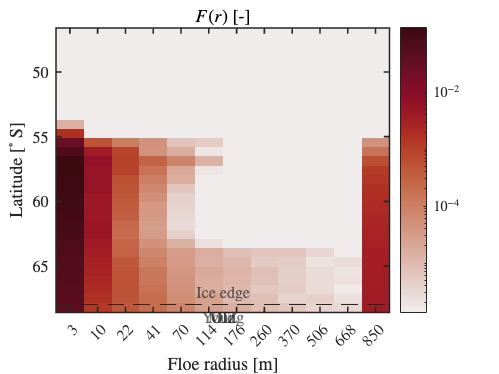


idx_tmp = aice_vec > 0.15;
ice_edge = find(idx_tmp);

conFigure(11,1)
f = figure;
imagesc(1:12,-lat_vec,afsd_vec), cmocean('balance','pivot',0)
yline(-ulat_vec(edge),'--',{'MIZ','Young','Old'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','bottom','Interpreter','latex')
yline(-ulat_vec(edge(1)),'--',{'Ice edge'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','top','Interpreter','latex')
xlabel('Floe radius [m]')
ylabel('Latitude [$^\circ$ S]')
xticks(1:12)
xticklabels(floe_ticks)
%yTickLabels(-lat_vec);
title("$F(r)$ [-]")
set(gca,'ColorScale','log')
colorbar

%saveas(f,'FSD-3dbar.png')

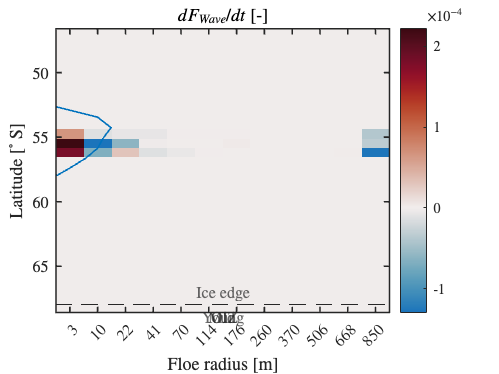




conFigure(11,1)
f = figure;
set(gca,'ColorScale','linear')
imagesc(1:12,-lat_vec,dafsd_wave_vec), cmocean('balance','pivot',0)
yline(-ulat_vec(edge),'--',{'MIZ','Young','Old'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','bottom','Interpreter','latex')
yline(-ulat_vec(edge(1)),'--',{'Ice edge'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','top','Interpreter','latex')
xlabel('Floe radius [m]')
ylabel('Latitude [$^\circ$ S]')
hold on
xticks(1:12)
xticklabels(floe_ticks)
%yTickLabels(-lat_vec);
title("$dF_{Wave}/dt$ [-]")
colorbar

%saveas(f,'FSD-wave-3dbar.png')


conFigure(11,1)
f = figure;
imagesc(1:12,-lat_vec,dafsd_newi_vec), cmocean('balance','pivot',0)
yline(-ulat_vec(edge),'--',{'MIZ','Young','Old'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','bottom','Interpreter','latex')
yline(-ulat_vec(edge(1)),'--',{'Ice edge'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','top','Interpreter','latex')
xlabel('Floe radius [m]')
ylabel('Latitude [$^\circ$ S]')
xticks(1:12)
xticklabels(floe_ticks)
%yTickLabels(-lat_vec);
title("$dF_{Newi}/dt$ [-]")
colorbar
saveas(f,'FSD-newi-3dbar.png')

conFigure(11,1)
f = figure;
imagesc(1:12,-lat_vec,dafsd_weld_vec), cmocean('balance','pivot',0)
yline(-ulat_vec(edge),'--',{'MIZ','Young','Old'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','bottom','Interpreter','latex')
yline(-ulat_vec(edge(1)),'--',{'Ice edge'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','top','Interpreter','latex')
xlabel('Floe radius [m]')
ylabel('Latitude [$^\circ$ S]')
xticks(1:12)
xticklabels(floe_ticks)
%yTickLabels(-lat_vec);
title("$dF_{Weld}/dt$ [-]")
colorbar
saveas(f,'FSD-weld-3dbar.png')
conFigure(11,1)
f = figure;
imagesc(1:12,-lat_vec,dafsd_latm_vec), cmocean('balance','pivot',0)
yline(-ulat_vec(edge),'--',{'MIZ','Young','Old'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','bottom','Interpreter','latex')
yline(-ulat_vec(edge(1)),'--',{'Ice edge'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','top','Interpreter','latex')
xlabel('Floe radius [m]')
ylabel('Latitude [$^\circ$ S]')
xticks(1:12)
xticklabels(floe_ticks)
%yTickLabels(-lat_vec);
title("$dF_{latm}/dt$ [-]")
colorbar
saveas(f,'FSD-latm-3dbar.png')

conFigure(11,1)
f = figure;
imagesc(1:12,-lat_vec,dafsd_latg_vec), cmocean('balance','pivot',0)
yline(-ulat_vec(edge),'--',{'MIZ','Young','Old'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','bottom','Interpreter','latex')
yline(-ulat_vec(edge(1)),'--',{'Ice edge'},'LabelHorizontalAlignment','center','LabelVerticalAlignment','top','Interpreter','latex')
xlabel('Floe radius [m]')
ylabel('Latitude [$^\circ$ S]')
xticks(1:12)
xticklabels(floe_ticks)
%yTickLabels(-lat_vec);
title("$dF_{latg}/dt$ [-]")
colorbar
saveas(f,'FSD-latg-3dbar.png')

%% Sectoral analysis


sector = "SH";
file_number = 1755;
filenames(file_number,:)

ans = '/Volumes/NoahDay5TB/WIM_on/history/fullyears/iceh.2019-10-21.nc'

NFSD = ncread(filenames(1700,:),'NFSD');
[floe_binwidth, floe_rad_l, floe_rad_h, floe_area_binwidth] = cice_parameters(NFSD);

afsd = data_format_sector(filenames(file_number,:), "afsd",sector);
dafsd_wave = data_format_sector(filenames(file_number,:), "dafsd_wave",sector);
dafsd_latg = data_format_sector(filenames(file_number,:), "dafsd_latg",sector);
dafsd_latm = data_format_sector(filenames(file_number,:), "dafsd_latm",sector);
dafsd_weld = data_format_sector(filenames(file_number,:), "dafsd_weld",sector);
dafsd_newi = data_format_sector(filenames(file_number,:), "dafsd_newi",sector);
[aice_data, sector_mask] = data_format_sector(filenames(file_number,:),'aice',sector);
wave_sig_ht = data_format_sector(filenames(file_number,:), "wave_sig_ht",sector);

row_file = [0,cumsum(row_idx)];
row_vec = row_file(file_number)+1:row_file(file_number+1);
temp_idx = kmeans_idx;
file_idx = temp_idx(row_vec);
file_idx = reshape(file_idx,length(file_idx),1);

[lat, lon, row, ulat] = grid_read('om2');
[len, wid] = size(lat);

X_map = [file_idx, Xnan(row_vec,end-1:end)];%[file_idx, X_new(:,end-1:end)];%
k_means = NaN.*ones(len,wid);
%var_data = NaN.*ones(len,wid);
for i = 1:length(file_idx)
    [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
    k_means(lon_pos,lat_pos) = file_idx(i); 
    %var_data(lon_pos,lat_pos) = X_new(i,var_idx);     
end
k_means(~sector_mask) = NaN;

% Get data along a longitude

% Pick a longitude
lon_pos = 31;
lon(lon_pos,1)

ans = 29.5000

lat_range = 30:60;
lon_range = lon_pos-10:lon_pos+10;

ulat_vec = ulat(lon_range,lat_range);
lat_vec = lat(lon_range,lat_range);
aice_vec = aice_data(lon_range,lat_range);
swh_vec = wave_sig_ht(lon_range,lat_range);
k_means_vec = mode(k_means(lon_range,lat_range));
afsd_vec = squeeze(mean(afsd(lon_range,lat_range,:)));
%dafsd_wave_vec = squeeze(mean(dafsd_wave(lon_range,lat_range,:)));
%dafsd_latg_vec = squeeze(mean(dafsd_latg(lon_range,lat_range,:)));
%dafsd_latm_vec = squeeze(mean(dafsd_latm(lon_range,lat_range,:)));
%dafsd_newi_vec = squeeze(mean(dafsd_newi(lon_range,lat_range,:)));
%dafsd_weld_vec = squeeze(mean(dafsd_weld(lon_range,lat_range,:)));

for i = lon_range
    for j = lat_range
        dafsd_wave_vec(i,j) = sum(squeeze(dafsd_wave(i,j,:)).*floe_binwidth');
    end
end

clear dafsd_weld dafsd_wave dafsd_latg dafsd_latm dafsd_newi afsd wave_sig_ht

close all
clear edge floe_ticks
for i = 1:12
    floe_ticks{i} = sprintf('%g',round(NFSD(i),0));
end
for i = 1:3
    idx = k_means_vec == i;
    edge_tmp = find(idx);
    %edge(i) = edge_tmp(end);
end
edge = [1,1,1]

edge =      1     1     1




figure;
w = worldmap('Antarctica');
            axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
            setm(w, 'Origin', [-90 0 0]);
            setm(w, 'maplatlimit', [-90 -50]);
            setm(w, 'maplonlimit', [lon(lon_range(1),1), lon(lon_range(end),1)]);

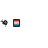

            
            %setm(w, 'maplonlimit', [coords(1,2),coords(3,2)]);
%             if sector == "EA"
%                 axesm eqdcylin; 
%                 setm(w, 'Origin', [0 28 0]); 
%                 setm(w, 'maplatlimit', [-75,-50]); setm(w, 'maplonlimit', [1,150]); 
                 setm(w, 'meridianlabel', 'off'); setm(w, 'parallellabel', 'off'); 
%                 setm(w, 'mlabellocation', 30); setm(w, 'plabellocation', 10); 
%                 setm(w, 'mlabelparallel', 'south','FontColor','black','FontSize',3);
                setm(w, 'grid', 'off');
%                 setm(w, 'labelrotation', 'on')
%             else
%                 axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
%                 setm(w, 'Origin', [-90 0 0]);
%                 setm(w, 'maplatlimit', [-90,-50]);
%                 setm(w, 'grid', 'off');
%                 setm(w, 'labelrotation', 'on')
%             end
            pcolorm(lat_vec,lon(lon_range,lat_range),dafsd_wave_vec)
            land = shaperead('landareas', 'UseGeoCoords', true);
            geoshow(w, land, 'FaceColor', [0.5 0.5 0.5])
            caxis([-50,50])
            cmocean('balance','pivot',0)
            cb = colorbar;
         %   title(dirdates(file_number,:),'Color','black','FontSize',font_size+5)
     
            cb.Location = 'eastoutside';
            
            cb.AxisLocation = 'in';

## Scatter of wave height and wave breakup

sector = "SH";
file_number = 1800;
filenames(file_number,:)

ans = '/Volumes/NoahDay5TB/WIM_on/history/fullyears/iceh.2019-12-05.nc'

NFSD = ncread(filenames(1700,:),'NFSD');
[floe_binwidth, floe_rad_l, floe_rad_h, floe_area_binwidth] = cice_parameters(NFSD);

swh = data_format_sector(filenames(file_number,:), "wave_sig_ht",sector);
aice = data_format_sector(filenames(file_number,:), "aice",sector);
ra = data_format_sector(filenames(file_number,:), "fsdrad",sector);
dafsd_wave = data_format_sector(filenames(file_number,:), "dafsd_wave",sector);

for i = 1:361
    for j = 1:300
        dafsd_wave_vec(i,j) = sum(squeeze(dafsd_wave(i,j,:)).*floe_binwidth');
    end
end

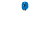

close all
f = figure;
scatter3(swh(:),dafsd_wave_vec(:),ra(:))
set(gca,'ZScale','log')
xlabel SWH
ylabel dF
zlabel F

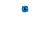

close all
f = figure;
scatter3(swh(:),dafsd_wave_vec(:),lon(:))
%set(gca,'ZScale','log')
xlabel SWH
ylabel dF
zlabel lon

sector = "SH";
file_number = 1755;
filenames(file_number,:)

ans = '/Volumes/NoahDay5TB/WIM_on/history/fullyears/iceh.2019-10-21.nc'

NFSD = ncread(filenames(1700,:),'NFSD');
[floe_binwidth, floe_rad_l, floe_rad_h, floe_area_binwidth] = cice_parameters(NFSD);

for file_number = 1:2
    %afsd = data_format_sector(filenames(file_number,:), "afsd",sector);
    dafsd_wave = data_format_sector(filenames(file_number,:), "dafsd_wave",sector);
    %dafsd_latg = data_format_sector(filenames(file_number,:), "dafsd_latg",sector);
    %dafsd_latm = data_format_sector(filenames(file_number,:), "dafsd_latm",sector);
    %dafsd_weld = data_format_sector(filenames(file_number,:), "dafsd_weld",sector);
    %dafsd_newi = data_format_sector(filenames(file_number,:), "dafsd_newi",sector);
    [aice(:,:,file_number), sector_mask] = data_format_sector(filenames(file_number,:),'aice',sector);
    wave_sig_ht(:,:,file_number) = data_format_sector(filenames(file_number,:), "wave_sig_ht",sector);

    for i = 1:361
        for j = 1:300
            dafsd_wave_r(i,j,file_number) = sum(squeeze(dafsd_wave(i,j,:)).*floe_binwidth');
        end
    end
    
    row_file = [0,cumsum(row_idx)];
    row_vec = row_file(file_number)+1:row_file(file_number+1);
    temp_idx = kmeans_idx;
    file_idx = temp_idx(row_vec);
    file_idx = reshape(file_idx,length(file_idx),1);
    
    [lat, lon, row, ulat] = grid_read('om2');
    [len, wid] = size(lat);
    
    X_map = [file_idx, Xnan(row_vec,end-1:end)];%[file_idx, X_new(:,end-1:end)];%
    k_means = NaN.*ones(len,wid);
    %var_data = NaN.*ones(len,wid);
    for i = 1:length(file_idx)
        [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
        k_means(lon_pos,lat_pos) = file_idx(i); 
        %var_data(lon_pos,lat_pos) = X_new(i,var_idx);     
    end
    k_means(~sector_mask) = NaN;

    k_means_cube(:,:,file_number) = k_means;

end
    

for i = 1:2
    temp = squeeze(wave_sig_ht(:,:,i));
    swh_vec(i,:) = temp(:);
end
 close all
 f = figure;
 scatter(1:file_number,swh_vec)





for i = lat_range
    afsd_sic_vec(i,:) = afsd_vec(i,:).*floe_binwidth;
end

Index in position 1 exceeds array bounds.
Index must not exceed 25.


close all
f = figure;
bar3(lat_vec,afsd_sic_vec)
xlabel("SIC [-]")
ylabel("Latitude [$^\circ$]")
zlabel("Floe size category [-]")

% Waves
f = figure;
b = bar3(lat_range ,dafsd_wave_vec,1);
xlabel("Floe size category [-]")
ylabel("Latitude [$^\circ$]")
zlabel("$dF_{Wave}/dt$ [-]")
for k = 1:length(b)
    zdata = b(k).ZData;
    b(k).CData = zdata;
    b(k).FaceColor = 'interp';
end
colorbar
%view(2)

close all
conFigure(11,1)
f = figure;
b = bar3(lat_range ,dafsd_weld_vec,1);
xlabel("Floe size category [-]")
ylabel("Latitude [$^\circ$]")
zlabel("$dF_{Weld}/dt$ [-]")
for k = 1:length(b)
    zdata = b(k).ZData;
    b(k).CData = zdata;
    b(k).FaceColor = 'interp';
end
xlim=get(gca,'xlim');
hold on
plot(xlim,[0.00001 0.00001])
colorbar
saveas(f,'FSD-weld-3dbar.png')

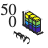

z = [19 30 21 30; 40 16 32 12; 40 16 32 12];
z(:,:,1) = [19 30 21 30; 40 16 32 12; 40 16 32 12]/2;
b = bar3(z,1,'stacked');

## Inner pack FSD constributions

C1 = linspecer(num_clusters);
Cmap = C1([1,3,2],:);
close all
conFigure(33,0.3)
f = figure;
tiledlayout(8,1)

x_floe = [floe_rad_l floe_rad_h(end)];

lat_pos = [50 40 30]; % MIZ, Young, Old
bottom = 0; %identify bottom; or use min(sh.YData)

nexttile(1,[2 1])
for i = 1:3
    stairs(x_floe, [fsd_cell(lat_pos(i),:)./aice_data(1,lat_pos(i))' fsd_cell(lat_pos(i),end)./aice_data(1,lat_pos(i))'],'LineWidth',2,'Color',Cmap(i,:))
    hold on
end
%stairs(x_floe, fsd_cell(lat_pos(2),:)./aice_data(1,lat_pos(2))','LineWidth',2,'Color',Cmap(2,:))
%stairs(x_floe, fsd_cell(lat_pos(3),:)./aice_data(1,lat_pos(3))','LineWidth',2,'Color',Cmap(3,:))
legend({'MIZ','Young','Older'},'Location','southwest','Orientation','vertical')
ylabel 'Density [m$^{-1}$]'
title 'Areal floe size distribution (PDF)'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
set(gca,'Yscale','log')
xlim([1,x_floe(end)])
ylim([1e-20 1])

% Breakup
nexttile
for i = 1:3
    sh = stairs(x_floe, [dafsd_wave_cell(lat_pos(i),:)'; dafsd_wave_cell(lat_pos(i),end)],'LineWidth',2,'Color',Cmap(i,:));
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none')
end
ylabel '$dF/dt$ [s$^{-1}$]'
title 'Change in areal FSD from waves'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([1,x_floe(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.001 0.001])

% New ice
nexttile
for i = 1:3
    sh = stairs(x_floe, [dafsd_newi_cell(lat_pos(i),:) dafsd_newi_cell(lat_pos(i),end)],'LineWidth',2,'Color',Cmap(i,:));
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none')
end
ylabel '$dF/dt$ [s$^{-1}$]'
title 'Change in areal FSD from new ice'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([1,x_floe(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.001 0.001])

% Welding
nexttile
for i = 1:3
    sh = stairs(x_floe, [dafsd_weld_cell(lat_pos(i),:) dafsd_weld_cell(lat_pos(i),end)],'LineWidth',2,'Color',Cmap(i,:));
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none')
end
ylabel '$dF/dt$ [s$^{-1}$]'
title 'Change in areal FSD from welding'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([1,x_floe(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.0001 0.0001])

% Lat melt
nexttile
for i = 1:3
    sh = stairs(x_floe, [dafsd_latm_cell(lat_pos(i),:) dafsd_latm_cell(lat_pos(i),end)],'LineWidth',2,'Color',Cmap(i,:));
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none')
end
ylabel '$dF/dt$ [s$^{-1}$]'
title 'Change in areal FSD from lateral melt'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([1,x_floe(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.0001 0.0001])

% Lat growth
nexttile
for i = 1:3
    sh = stairs(x_floe, [dafsd_latg_cell(lat_pos(i),:) dafsd_latg_cell(lat_pos(i),end)],'LineWidth',2,'Color',Cmap(i,:));
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none')
end


ylabel '$dF/dt$ [s$^{-1}$]'
title 'Change in areal FSD from lateral growth'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([1,x_floe(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.00000001 0.00000001])


% Total change
clear dafsd_total
nexttile
for i = 1:3
    dafsd_total(i,1:12) = dafsd_wave_cell(lat_pos(i),:)+dafsd_weld_cell(lat_pos(i),:)+dafsd_newi_cell(lat_pos(i),:)+dafsd_latg_cell(lat_pos(i),:)+dafsd_latm_cell(lat_pos(i),:);
    dafsd_total(i,13) =  dafsd_total(i,12);
    sh = stairs(x_floe, dafsd_total(i,:)','LineWidth',2,'Color',Cmap(i,:));
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none')
end


%area(floe_rad_l, dafsd_total(1,:)','FaceColor',Cmap(1,:))
%hold on
%area(floe_rad_l, dafsd_total(2,:)','FaceColor',Cmap(2,:))
%area(floe_rad_l, dafsd_total(3,:)','FaceColor',Cmap(3,:))

ylabel '$dF/dt$ [s$^{-1}$]'
title 'Total change in areal FSD'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([1,x_floe(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.001 0.001])

exportgraphics(f,'FSD-contribution-comp.pdf','ContentType','vector')

C1 = linspecer(num_clusters);
Cmap = C1([1,3,2],:);
close all
conFigure(33,2)
f = figure;
tiledlayout(3,2)

x_floe = [floe_rad_l floe_rad_h(end)];

lat_pos = [50 40 30]; % MIZ, Young, Old
bottom = 0; %identify bottom; or use min(sh.YData)

nexttile(1,[3 1])
for i = 1:3
    stairs(x_floe, [fsd_cell(lat_pos(i),:)./aice_data(1,lat_pos(i))' fsd_cell(lat_pos(i),end)./aice_data(1,lat_pos(i))'],'LineWidth',2,'Color',Cmap(i,:))
    hold on
end
%stairs(x_floe, fsd_cell(lat_pos(2),:)./aice_data(1,lat_pos(2))','LineWidth',2,'Color',Cmap(2,:))
%stairs(x_floe, fsd_cell(lat_pos(3),:)./aice_data(1,lat_pos(3))','LineWidth',2,'Color',Cmap(3,:))
legend({'MIZ','Young','Older'},'Location','southwest','Orientation','vertical')
ylabel 'Density [m$^{-1}$]'
title 'Areal floe size distribution (PDF)'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
set(gca,'Yscale','log')
xlim([1,x_floe(end)])
ylim([1e-20 1])

% MIZ, young, old
title_vec = {"MIZ", "Young", "Old"};
for i = 1:3
nexttile
    % 
    sh = stairs(x_floe, [dafsd_wave_cell(lat_pos(i),:)'; dafsd_wave_cell(lat_pos(i),end)],'LineWidth',2,'color',"#0072BD");
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none','HandleVisibility','off')

    sh = stairs(x_floe, [dafsd_newi_cell(lat_pos(i),:)'; dafsd_newi_cell(lat_pos(i),end)],'LineWidth',2,'color',"#EDB120");
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none','HandleVisibility','off')

    sh = stairs(x_floe, [dafsd_weld_cell(lat_pos(i),:)'; dafsd_weld_cell(lat_pos(i),end)],'LineWidth',2,'color',"#D95319");
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none','HandleVisibility','off')

    sh = stairs(x_floe, [dafsd_latm_cell(lat_pos(i),:)'; dafsd_latm_cell(lat_pos(i),end)],'LineWidth',2,'color',"#A2142F");
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none','HandleVisibility','off')

    sh = stairs(x_floe, [dafsd_latg_cell(lat_pos(i),:)'; dafsd_latg_cell(lat_pos(i),end)],'LineWidth',2,'color',"#77AC30");
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none','HandleVisibility','off')
    ylabel '$dF/dt$ [s$^{-1}$]'
    title(title_vec(i))
    
    set(gca,'Xscale','log')
    %grid on
    xlim([1,x_floe(end)])
    yline(0,'--','Color',[0.5, 0.5, 0.5])
    ylim([-0.001 0.001])
    if i == 1
        legend('Wave','New ice','Welding','Latm','Latg','Location','northoutside','Orientation','Horizontal')
    end
    if i == 3
        xlabel 'Floe size [m]'
    end
end
exportgraphics(f,'FSD-contribution-comp-region.pdf','ContentType','vector')



% New ice
nexttile
for i = 1:3
    sh = stairs(x_floe, [dafsd_newi_cell(lat_pos(i),:) dafsd_newi_cell(lat_pos(i),end)],'LineWidth',2,'Color',Cmap(i,:));
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none')
end
ylabel '$dF/dt$ [s$^{-1}$]'
title 'Change in areal FSD from new ice'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([1,x_floe(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.001 0.001])

% Welding
nexttile
for i = 1:3
    sh = stairs(x_floe, [dafsd_weld_cell(lat_pos(i),:) dafsd_weld_cell(lat_pos(i),end)],'LineWidth',2,'Color',Cmap(i,:));
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none')
end
ylabel '$dF/dt$ [s$^{-1}$]'
title 'Change in areal FSD from welding'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([1,x_floe(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.0001 0.0001])

% Lat melt
nexttile
for i = 1:3
    sh = stairs(x_floe, [dafsd_latm_cell(lat_pos(i),:) dafsd_latm_cell(lat_pos(i),end)],'LineWidth',2,'Color',Cmap(i,:));
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none')
end
ylabel '$dF/dt$ [s$^{-1}$]'
title 'Change in areal FSD from lateral melt'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([1,x_floe(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.0001 0.0001])

% Lat growth
nexttile
for i = 1:3
    sh = stairs(x_floe, [dafsd_latg_cell(lat_pos(i),:) dafsd_latg_cell(lat_pos(i),end)],'LineWidth',2,'Color',Cmap(i,:));
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none')
end


ylabel '$dF/dt$ [s$^{-1}$]'
title 'Change in areal FSD from lateral growth'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([1,x_floe(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.00000001 0.00000001])


% Total change
clear dafsd_total
nexttile
for i = 1:3
    dafsd_total(i,1:12) = dafsd_wave_cell(lat_pos(i),:)+dafsd_weld_cell(lat_pos(i),:)+dafsd_newi_cell(lat_pos(i),:)+dafsd_latg_cell(lat_pos(i),:)+dafsd_latm_cell(lat_pos(i),:);
    dafsd_total(i,13) =  dafsd_total(i,12);
    sh = stairs(x_floe, dafsd_total(i,:)','LineWidth',2,'Color',Cmap(i,:));
    hold on
    x = [sh.XData(1),repelem(sh.XData(2:end),2)];
    y = [repelem(sh.YData(1:end-1),2),sh.YData(end)];
    fill([x,fliplr(x)],[y,bottom*ones(size(y))],Cmap(i,:),'FaceAlpha',0.2,'edgecolor','none')
end


%area(floe_rad_l, dafsd_total(1,:)','FaceColor',Cmap(1,:))
%hold on
%area(floe_rad_l, dafsd_total(2,:)','FaceColor',Cmap(2,:))
%area(floe_rad_l, dafsd_total(3,:)','FaceColor',Cmap(3,:))

ylabel '$dF/dt$ [s$^{-1}$]'
title 'Total change in areal FSD'
xlabel 'Floe size [m]'
set(gca,'Xscale','log')
%grid on
xlim([1,x_floe(end)])
yline(0,'--','Color',[0.5, 0.5, 0.5])
ylim([-0.001 0.001])

exportgraphics(f,'FSD-contribution-comp-proc.pdf','ContentType','vector')


% Create Fancharts
for i = file_number_vec
    var_vec(i,:) = reshape(var_layer(1,i,:,:),[numel(var_layer(1,i,:,:)),1]);
end

for i = file_number_vec
    var_vec2(i,:) = reshape(var_layer(2,i,:,:),[numel(var_layer(2,i,:,:)),1]);
end

for i = file_number_vec
    var_vec3(i,:) = reshape(var_layer(3,i,:,:),[numel(var_layer(3,i,:,:)),1]);
end

conFigure(10)
    f = figure;
    %fanChart(datetime(dirdates(file_number_vec,:)),var_vec(file_number_vec,1:1000))
    plot(nanstd(var_vec(file_number_vec,:)'),'linewidth',3)
    hold on
    plot(nanstd(var_vec2(file_number_vec,:)'),'linewidth',3)
    plot(nanstd(var_vec3(file_number_vec,:)'),'linewidth',3)
    ylabel(strcat("STD ",label_vec(var_idx)))
    legend('MIZ','Young','Older','Location','southoutside','Orientation','horizontal')
    title(label_vec(var_idx))
    exportgraphics(f,strcat('timeseries_STD_',var_list{var_idx},'.pdf'),'ContentType','vector')




## Testing MIZ width    

clear area_region MIZ_width MIZ_width_corrected X_map
SIC = 0.15;
pram.ice_edge_color = 0.7*[0.4660 0.6740 0.1880];
line_width = 1;

addpath functions
[lat,lon,~,ulat,ulon] = grid_read('om2');

% Make worldmap with colour matching
uarea = data_format(filenames(1,:),"uarea");

[num_files,~] = size(filenames);
sector = "SH";
coords = sector_coords(sector);
font_size = 5;
%for var_idx = 1:22
var_idx = 5;
var_name = var_list{var_idx};
var_name = "dafsd_wave_vec";
plotting = "off";


X_new = Xnan(:,:);
[len,wid] = size(lat);

MIZ_width = [];
MIZ_width_corrected = [];
    

file_number_vec = 1826-365:1:1826;
for file_number = file_number_vec 
    row_file = [0,cumsum(row_idx)];
    row_vec = row_file(file_number)+1:row_file(file_number+1);
    temp_idx = kmeans_idx;
    file_idx = temp_idx(row_vec);
    file_idx = reshape(file_idx,length(file_idx),1);

    [aice, sector_mask] = data_format_sector(filenames(file_number,:),'aice',sector);
    X_map = [file_idx, X_new(row_vec,end-1:end)];%
    k_means = NaN.*ones(len,wid);
    for i = 1:length(file_idx)
        [lon_pos,lat_pos,~] = near2(lon,lat,X_map(i,3),X_map(i,2));
        k_means(lon_pos,lat_pos) = file_idx(i);    
    end
    k_means(~sector_mask) = NaN;
    if var_idx > 17 % DAFSD variables
        temp_data = data_format_sector(filenames(file_number,:), var_name,sector);
        NFSD = ncread(filenames(file_number,:),'NFSD');
        [floe_binwidth, floe_rad_l, floe_rad_h, floe_area_binwidth] = cice_parameters(NFSD);
        var_data = zeros(size(aice));
        for nf = 1:numel(NFSD)
            var_data = var_data + temp_data(:,:,nf).*floe_binwidth(nf);
        end
    elseif var_name == "dafsd_wave"
        temp_data = data_format_sector(filenames(file_number,:), var_name,sector);
        var_data = squeeze(temp_data(:,:,12));
    elseif var_name == "dafsd_wave_vec"
        temp_data = data_format_sector(filenames(file_number,:), "dafsd_wave",sector);
        var_data = temp_data; %squeeze(temp_data(:,:,12));
    else
        var_data = data_format_sector(filenames(file_number,:),var_name,sector);
    end
    ice_mask =  aice > 0.15;
    var_data(~ice_mask) = NaN;
    

    [MIZ_width_temp,MIZ_width_corrected_temp, miz_class, MIZ_zone, aice_width] = calculate_miz_width(convertStringsToChars(filenames(file_number,:)),sector,k_means,miz_def); % Number corresponding to MIZ at end

    MIZ_width = [MIZ_width, MIZ_width_temp(1:360)]; % Remove the patch
    MIZ_width_corrected = [MIZ_width_corrected, MIZ_width_corrected_temp(1:360)]; % Remove the patch

end
    

lon_pos = 1;
lat_vec = lat(lon_pos,:);
close all
f = figure;
plot(lat_vec, k_means(lon_pos,:),'o')
ylim([0,4])
xlabel('Latitude [$^\circ$]')
pos = find(k_means(lon_pos,:) == 1);
south_point = pos(1);
north_point = pos(end);
pathdist([lat(lon_pos,south_point-1),lat(lon_pos,north_point)],[lon(lon_pos,south_point-1),lon(lon_pos,south_point-1)],'km');







corrected_MIZs = MIZ_width_corrected';
corrected_MIZs_vec = reshape(corrected_MIZs,numel(corrected_MIZs),1);
[N,edges] = histcounts(corrected_MIZs_vec);
conFigure(11,3)
f = figure;
histogram(corrected_MIZs_vec(~isnan(corrected_MIZs_vec)))
ylabel('Frequency')
xlabel('Corrected MIZ width [km]')
xlim([0,450])
exportgraphics(f,'mizwidth_hist.pdf','ContentType','vector')
%matlab2tikz('mizwidth_hist.tex', 'standalone', true);


close all
A={randn(1,10^5),randn(10^3,1)+1};
nhist(A,'legend',{'u=0','u=1'});
nhist(A,'legend',{'u=0','u=1'},'separate');






conFigure(11)
f = figure;
set(gcf,'Visible', 'on')
w = worldmap('world');
    axesm eqaazim; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-53]);
    setm(w, 'grid', 'off');
    setm(w, 'frame', 'off');
    %setm(w, 'MLineLimit',[-60,-75]);
    %setm(w,'MLineException',[-90 0 90 180])
    setm(w, "FontColor",[0.5, 0.5, 0.5])
    setm(w, 'labelrotation', 'on')
    setm(w, 'meridianlabel', 'on','FontSize',font_size)
    setm(w, 'parallellabel', 'off','FontSize',font_size)
    setm(w, 'mlabellocation', 60);
    setm(w, 'plabellocation', 5);
    pcolorm(lat,lon,k_means,'FaceAlpha',0.99)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.5 0.5],'FaceAlpha',.5)
    colorbar; %cmocean('deep');
    %colormap(Cmap)
    %cb = colorbar;
    title(dirdates(file_number,:),'Color','black','FontSize',font_size+3)
    scalebar('length',1000,...
        'units','km',...
        'color','k','location','sw',...
        'fontangle','italic','FontSize',font_size)
    cb = colorbar; cmocean('deep',num_clusters)
    %cb.TickLabels = region_label; 
    cb.Ticks = 1:num_clusters;
    cb.Location = 'southoutside';%cb.Location = 'northoutside';
    cb.Location = 'eastoutside';
    caxis([0.5,num_clusters+0.5])
    cb.AxisLocation = 'out';
    cb.FontSize = font_size+3;
exportgraphics(f,'map.pdf','ContentType','vector')


% Seasonal histogram of MIZ widths

day_of_year = mod(file_number_vec,365)
summer_days = day_of_year <= (31+28) | day_of_year > 365-31;
autumn_days = (31+28) < day_of_year & day_of_year <=  (31+28+31+30+31);
winter_days = (31+28+31+30+31) < day_of_year & day_of_year <=  (31+28+31+30+31+30+31+31);
spring_days = (31+28+31+30+31+30+31+31) < day_of_year & day_of_year <=  (31+28+31+30+31+30+31+31+30+31+30);

MIZ_width_year = MIZ_width_corrected;

% Make scatter of MIZ with colored dots for each season/month

%f = figure;
%plot(day_of_year(summer_days),MIZ_width_year(summer_days,:),'o','Color','r')
%hold on
%plot(day_of_year(autumn_days),MIZ_width_year(autumn_days,:),'o','Color','yellow')
%plot(day_of_year(winter_days),MIZ_width_year(winter_days,:),'o','Color','b')
%plot(day_of_year(spring_days),MIZ_width_year(spring_days,:),'o','Color','g')
% Top two plots
conFigure(11)
f = figure;
histogram(reshape(MIZ_width_year(:,summer_days),numel(MIZ_width_year(:,summer_days)),1),edges,'FaceAlpha',0,'FaceColor',"#D95319",'EdgeColor',"#D95319")%,'DisplayStyle','stairs','LineWidth',2)
hold on
histogram(reshape(MIZ_width_year(:,autumn_days),numel(MIZ_width_year(:,autumn_days)),1),edges,'FaceAlpha',0,'FaceColor',"#EDB120",'EdgeColor',"#EDB120")%,'DisplayStyle','stairs','LineWidth',2)
histogram(reshape(MIZ_width_year(:,winter_days),numel(MIZ_width_year(:,winter_days)),1),edges,'FaceAlpha',0,'FaceColor',"#0072BD",'EdgeColor',"#0072BD")%,'DisplayStyle','stairs','LineWidth',2)
histogram(reshape(MIZ_width_year(:,spring_days),numel(MIZ_width_year(:,spring_days)),1),edges,'FaceAlpha',0,'FaceColor',"#77AC30",'EdgeColor',"#77AC30")%,'DisplayStyle','stairs','LineWidth',2)
legend('Summer','Autumn','Winter','Fall')

clear A
%colormap(["#D95319" "#EDB120" "#0072BD" "#77AC30"])
temp = reshape(MIZ_width_year(:,summer_days),numel(MIZ_width_year(:,summer_days)),1);
A.Summer = temp(~isnan(temp));
temp = reshape(MIZ_width_year(:,autumn_days),numel(MIZ_width_year(:,autumn_days)),1);
A.Autumn = temp(~isnan(temp));
temp = reshape(MIZ_width_year(:,winter_days),numel(MIZ_width_year(:,winter_days)),1);
A.Winter = temp(~isnan(temp));
temp = reshape(MIZ_width_year(:,spring_days),numel(MIZ_width_year(:,spring_days)),1);
A.Spring = temp(~isnan(temp));



close all
conFigure(11,1)
f = figure;
t = tiledlayout(2,1,'TileSpacing','compact')
nexttile
nhist(corrected_MIZs_vec(~isnan(corrected_MIZs_vec)))
xticklabels('')
set(gca,'YScale','linear')
nexttile
nhist(A,'samebins','noerror')
ylim([0,0.02])
xlabel('Corrected MIZ width [km]')
exportgraphics(f,'MIZ_hist.pdf','ContentType','vector')
%xlim([10,500])
addpath /Users/noahday/Documents/MATLAB/matlab2tikz/src/
matlab2tikz('mizwidth_hist_season.tex', 'standalone', true);








tiledlayout(4,1)
conFigure(11)
f = figure;
nexttile
histogram(reshape(MIZ_width_year(:,summer_days),numel(MIZ_width_year(:,summer_days)),1),edges,'FaceAlpha',0.2,'FaceColor',"#D95319",'EdgeColor',"#D95319")%,'DisplayStyle','stairs','LineWidth',2)
title('Summer')
nexttile
histogram(reshape(MIZ_width_year(:,autumn_days),numel(MIZ_width_year(:,autumn_days)),1),edges,'FaceAlpha',0.2,'FaceColor',"#EDB120",'EdgeColor',"#EDB120")%,'DisplayStyle','stairs','LineWidth',2)
title('Autumn')
nexttile
histogram(reshape(MIZ_width_year(:,winter_days),numel(MIZ_width_year(:,winter_days)),1),edges,'FaceAlpha',0.2,'FaceColor',"#0072BD",'EdgeColor',"#0072BD")%,'DisplayStyle','stairs','LineWidth',2)
title('Winter')
nexttile
histogram(reshape(MIZ_width_year(:,spring_days),numel(MIZ_width_year(:,spring_days)),1),edges,'FaceAlpha',0.2,'FaceColor',"#77AC30",'EdgeColor',"#77AC30")%,'DisplayStyle','stairs','LineWidth',2)
title('Spring')
%exportgraphics(f,'mizwidth_hist_season.pdf','ContentType','vector')
%matlab2tikz('mizwidth_hist_season.tex', 'standalone', true);



lon_vec = lon(:,1);
% Summer
[~,len] = size(MIZ_width_year(:,summer_days));
MIZ_width_summer_vec = reshape(MIZ_width_year(:,summer_days),numel(MIZ_width_year(:,summer_days)),1);
lon_summer_vec = repmat(lon_vec', 1, len);
% Autumn
[~,len] = size(MIZ_width_year(:,autumn_days));
MIZ_width_autumn_vec = reshape(MIZ_width_year(:,autumn_days),numel(MIZ_width_year(:,autumn_days)),1);
lon_autumn_vec = repmat(lon_vec', 1, len);
% Winter
[~,len] = size(MIZ_width_year(:,winter_days));
MIZ_width_winter_vec = reshape(MIZ_width_year(:,winter_days),numel(MIZ_width_year(:,winter_days)),1);
lon_winter_vec = repmat(lon_vec', 1, len);
% Spring
[~,len] = size(MIZ_width_year(:,spring_days));
MIZ_width_spring_vec = reshape(MIZ_width_year(:,spring_days),numel(MIZ_width_year(:,spring_days)),1);
lon_spring_vec = repmat(lon_vec', 1, len);

conFigure(11)
f = figure;
plot(lon_summer_vec, MIZ_width_summer_vec, '+','Color',"#D95319")
hold on
plot(lon_autumn_vec, MIZ_width_autumn_vec, '+','Color',"#EDB120")
plot(lon_winter_vec, MIZ_width_winter_vec, '+','Color',"#0072BD")
plot(lon_spring_vec, MIZ_width_spring_vec, '+','Color',"#77AC30")
legend('Summer','Autumn','Winter','Spring')
xlabel('Longitude [$^\circ$ S]')
ylabel('Corrected MIZ width [km]')

%legend('Summer','Autumn','Winter','Spring')


## Change in MIZ widths

filename = "/Volumes/NoahDay1TB/sea-ice-classification/data/kmean_2015.nc";
ncdisp(filename)

Source:
           /Volumes/NoahDay1TB/sea-ice-classification/data/kmean_2015.nc
Format:
           netcdf4
Global Attributes:
           creation_date = '2023-04-07'
           conventions   = ''
           title         = 'k-means clusters for CICE-WIM standalone 1-degree data'
           source        = ', '
           comment       = ''
           author        = 'Noah Day'
           email         = 'noah.day@adelaide.edu.au'
Dimensions:
           time = 365   (UNLIMITED)
           nj   = 300
           ni   = 360
Variables:
    k          
           Size:       360x300x365
           Dimensions: ni,nj,time
           Datatype:   double
           Attributes:
                       _FillValue  = -200000000
                       long_name   = 'k-means_clusters'
                       units       = 'cluster number'
                       coordinates = 'LAT LON'
    aice       
           Size:       360x300x365
           Dimensions: ni,nj,time
           Datatype:   double
    

k = ncread(filename,"k");
%plot_k = 

close all
%C1 = linspecer(3);
%Cmap = C1([2,3,1],:);
Cmap = [0.9805, 0.5000, 0.4453; 0.4416, 0.7490, 0.4322; 0.3639, 0.5755, 0.748];
Cmap = Cmap([1,2,3],:);
%Cmap(1,:) = [251,128,114]/256;
lat = ncread(filename,"LAT");
lon = ncread(filename,"LON");

delta_m_label = 60;
linewidth_shelf = 0.5;
linewidth_coast = 1.0;

plot_lon = lon;
plot_lon(end+1,:) = (lon(1,:));% + lon(end,:))/2;
plot_lat = lat;
plot_lat(end+1,:) = (lat(1,:) + lat(end,:))/2;
plot_data = k(:,:,60); % March 1st
plot_data(end+1,:) = plot_data(1,:);
%plot_data(plot_data>0) = 1;
landmask = ncread(filename,'tmask');
landmask(end+1,:) = landmask(1,:);


nIDs = 4;
alphabet = ('a':'z').';
chars = num2cell(alphabet(1:nIDs));
chars = chars.';
charlbl = strcat(chars,')'); % {'(a)','(b)','(c)','(d)'}
font_size = 16;

% charlbl{1} = 'a) March'
% charlbl{2} = 'b) May'
% charlbl{3} = 'c) September'
% charlbl{4} = 'd) Decemeber'


close all
conFigure(11,1)
f = figure;
f = figure('position', [5, 5, 20, 10]) %,[0 0 20 10])

f =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [5 5 20 10]
       Units: 'centimeters'

  Show all properties


%subplot(1,2,1)
%antmap('grid')
tiledlayout(1,nIDs, 'Padding', 'none', 'TileSpacing', 'compact'); 
nexttile
w = worldmap('world');
    axesm eqaazim;
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-51]);
    setm(w, 'grid', 'on');
    setm(w, 'mlinelimit', [-80 -60]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', delta_m_label);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlinelocation', 60);
    setm(w, 'plinelocation', 10);
    setm(w, 'mlabelparallel', -55);
    setm(w, 'PLabelMeridian', 30);
    setm(w, 'labelrotation', 'on')
    pcolorm(plot_lat,plot_lon,plot_data);
    colormap(Cmap)
    %bedmap2('patchgl','linewidth',2,'facealpha',1.0);
    bedmap2('patchgl','facecolor',[0.6,0.6,0.6],'edgecolor',[0.3,0.3,0.3],'linewidth',linewidth_coast)
    bedmap2('patchshelves','facecolor',[0.9 0.9 0.9],'oceancolor','None','linewidth',linewidth_shelf,'linestyle','-')
    %outlineashelf('all','color','k');
    %scalebar('color','k','units','km','location','se')
%     scalebar('length',1000,...
%         'units','km',...
%         'color','k','location','se',...
%         'fontangle','italic')%,'FontSize',font_size)
text(0.025,0.95,charlbl{1},'Units','normalized','FontSize',font_size)
axis off

nexttile
plot_data = k(:,:,121+31); % June 1st
plot_data(end+1,:) = plot_data(1,:);
   w = worldmap('world');
    axesm eqaazim;
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-51]);
    setm(w, 'maplonlimit', [0,360]);

    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off')
  
    setm(w, 'mlinelimit', [-80 -60]);
    setm(w, 'meridianlabel', 'off')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', delta_m_label);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlinelocation', 60);
    setm(w, 'plinelocation', 10);
    setm(w, 'mlabelparallel', -53);
    %setm(w, 'mlinelimit', [-80 -60]);
    
    %setm(w, 'plinelimit', [-75 -65]);
    setm(w, 'labelrotation', 'on')
    %setm(w, 'Mlinelimit',[-75,75])
    pcolorm(plot_lat,plot_lon,plot_data);
    colormap(Cmap)
    %bedmap2('patchgl','linewidth',2,'facealpha',1.0);
    bedmap2('patchgl','facecolor',[0.6,0.6,0.6],'edgecolor',[0.3,0.3,0.3],'linewidth',linewidth_coast)
    bedmap2('patchshelves','facecolor',[0.9 0.9 0.9],'oceancolor','None','linewidth',linewidth_shelf,'linestyle','-')
    %outlineashelf('all','color','k');
    %scalebar('color','k','units','km','location','se')
%     scalebar('length',1000,...
%         'units','km',...
%         'color','k','location','sw',...
%         'fontangle','italic')%,'FontSize',font_size)
text(0.025,0.95,charlbl{2},'Units','normalized','FontSize',font_size)
box off
axis off


%subplot(1,2,2)
nexttile
plot_data = k(:,:,244); % September
plot_data(end+1,:) = plot_data(1,:);
   w = worldmap('world');
    axesm eqaazim;
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-51]);
    setm(w, 'maplonlimit', [0,360]);

    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off')
  
    setm(w, 'mlinelimit', [-80 -60]);
    setm(w, 'meridianlabel', 'off')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', delta_m_label);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlinelocation', 60);
    setm(w, 'plinelocation', 10);
    setm(w, 'mlabelparallel', -53);
    %setm(w, 'mlinelimit', [-80 -60]);
    
    %setm(w, 'plinelimit', [-75 -65]);
    setm(w, 'labelrotation', 'on')
    %setm(w, 'Mlinelimit',[-75,75])
    pcolorm(plot_lat,plot_lon,plot_data);
    colormap(Cmap)
    %bedmap2('patchgl','linewidth',2,'facealpha',1.0);
    bedmap2('patchgl','facecolor',[0.6,0.6,0.6],'edgecolor',[0.3,0.3,0.3],'linewidth',linewidth_coast)
    bedmap2('patchshelves','facecolor',[0.9 0.9 0.9],'oceancolor','None','linewidth',linewidth_shelf,'linestyle','-')
    %outlineashelf('all','color','k');
    %scalebar('color','k','units','km','location','se')
%     scalebar('length',1000,...
%         'units','km',...
%         'color','k','location','sw',...
%         'fontangle','italic')%,'FontSize',font_size)
text(0.025,0.95,charlbl{3},'Units','normalized','FontSize',font_size)
box off
axis off

nexttile
plot_data = k(:,:,334); % December
plot_data(end+1,:) = plot_data(1,:);
   w = worldmap('world');
    axesm eqaazim;
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-51]);
    setm(w, 'maplonlimit', [0,360]);

    setm(w, 'grid', 'on');
    setm(w, 'frame', 'off')
  
    setm(w, 'mlinelimit', [-80 -60]);
    setm(w, 'meridianlabel', 'off')
    setm(w, 'parallellabel', 'off')
    setm(w, 'mlabellocation', delta_m_label);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlinelocation', 60);
    setm(w, 'plinelocation', 10);
    setm(w, 'mlabelparallel', -53);
    %setm(w, 'mlinelimit', [-80 -60]);
    
    %setm(w, 'plinelimit', [-75 -65]);
    setm(w, 'labelrotation', 'on')
    %setm(w, 'Mlinelimit',[-75,75])
    pcolorm(plot_lat,plot_lon,plot_data);
    colormap(Cmap)
    %bedmap2('patchgl','linewidth',2,'facealpha',1.0);
    bedmap2('patchgl','facecolor',[0.6,0.6,0.6],'edgecolor',[0.3,0.3,0.3],'linewidth',linewidth_coast)
    bedmap2('patchshelves','facecolor',[0.9 0.9 0.9],'oceancolor','None','linewidth',linewidth_shelf,'linestyle','-')
    %outlineashelf('all','color','k');
    %scalebar('color','k','units','km','location','se')
%     scalebar('length',1000,...
%         'units','km',...
%         'color','k','location','sw',...
%         'fontangle','italic')%,'FontSize',font_size)
text(0.025,0.95,charlbl{4},'Units','normalized','FontSize',font_size)
box off
axis off


set(handlem('frame'),'clipping','off')

exportgraphics(f,'worldmap_2019-4-panes.png', 'ContentType', 'image','Resolution',1000)%,'BackgroundColor','none','Resolution',1000)
exportgraphics(f,'worldmap_2019-4-panes.pdf', 'ContentType', 'vector')

figure('position',[100 100 1000 400])
subplot(1,3,1)
antmap('grid')              % initializes left map and plots grid

patchm(plot_lat(:,1),plot_lon(1,:),'y')        % plots yellow continent atop grid

Error using patchm>validateLatLonZ
Function PATCHM expected its
LAT and LON inputs to have
the same size.

Error in patchm (line 37)
validateLatLonZ(lat, lon, z);


subplot(1,3,2)
antmap                      % initializes center map
patchm(plot_lat(:,1),plot_lon(1,:),'b')        % plots blue continent
antmap('grid','color','m')  % overlays magenta grid atop continent

subplot(1,3,3)
antmap('lats',-80:10:-50,...% Initializes & plots lines at 50, 60, 70, & 80 S
    'lons',0:45:180,...     % and 0, 45, 95, etc longitude
    'color','red',...       % in red
    'linewidth',2,...       % kinda thick
    'linestyle',':',...     % and dotted
    'oceancolor',rgb('ocean blue')) % and sets ocean color.
patchm(plot_lat(:,1),plot_lon(1,:),[.5 .5 .5]) % plot gray continent

plot_lon = lon;
plot_lon(end+1,:) = (lon(1,:));% + lon(end,:))/2;
plot_lat = lat;
plot_lat(end+1,:) = (lat(1,:) + lat(end,:))/2;
plot_data = k(:,:,150+90); %273
plot_data(end+1,:) = plot_data(1,:);
plot_data(plot_data>0) = 1;
landmask = ncread(filename,'tmask');
landmask(end+1,:) = landmask(1,:);

close all
conFigure(11)
f = figure;
w = worldmap('world');
    axesm eqaazim;
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-53]);
    setm(w, 'maplonlimit', [0,360]);

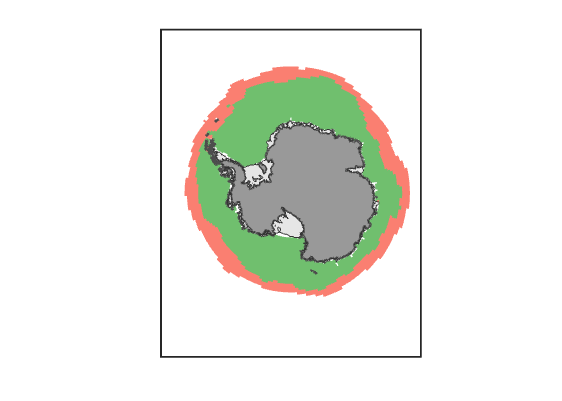

    setm(w, 'grid', 'off');
    setm(w, 'frame', 'off')
    pcolorm(plot_lat,plot_lon,plot_data);
    colormap(Cmap)
    bedmap2('patchgl','facecolor',[0.6,0.6,0.6],'edgecolor',[0.3,0.3,0.3],'linewidth',1.5)
    bedmap2('patchshelves','facecolor',[0.9 0.9 0.9],'oceancolor','None')

    %bedmap2('patchgl');
    %outlineashelf('all','color',[0.5,0.5,0.5],'linewidth',1);
    %outlineashelf('all','color','k','linewidth',1);
exportgraphics(f,'worldmap_2015-08-30-alberto.png', 'ContentType', 'image','Resolution',1000)

% Plots for Alberto
close all
C1 = linspecer(3);
Cmap = C1([2,3,1],:);
Cmap(1,:) = [251,128,114]/256;
lat = ncread(filename,"LAT");
lon = ncread(filename,"LON");


plot_lon = lon;
plot_lon(end+1,:) = (lon(1,:));% + lon(end,:))/2;
plot_lat = lat;
plot_lat(end+1,:) = (lat(1,:) + lat(end,:))/2;
plot_data = k(:,:,90);
plot_data(end+1,:) = plot_data(1,:);
landmask = ncread(filename,'tmask');
landmask(end+1,:) = landmask(1,:);

close all
conFigure(11)
f = figure;
t = tiledlayout(1,2, 'Padding', 'none', 'TileSpacing', 'compact'); 
nexttile
w = worldmap('world');
    axesm eqaazim;
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-62]);
    setm(w, 'maplonlimit', [0,360]);

    setm(w, 'grid', 'off');
    setm(w, 'frame', 'on')
    pcolorm(plot_lat,plot_lon,plot_data);
    colormap(Cmap)
    bedmap2('patchgl');
    %outlineashelf('all','color','k');
    %scalebar('color','k','units','km','location','se')
    scalebar('length',1000,...
        'units','km',...
        'color','k','location','sw',...
        'fontangle','italic')%,'FontSize',font_size)

nexttile
plot_lon = lon;
plot_lon(end+1,:) = (lon(1,:));% + lon(end,:))/2;
plot_lat = lat;
plot_lat(end+1,:) = (lat(1,:) + lat(end,:))/2;
plot_data = k(:,:,273);
plot_data(end+1,:) = plot_data(1,:);
landmask = ncread(filename,'tmask');
landmask(end+1,:) = landmask(1,:);

w = worldmap('world');
    axesm eqaazim;
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-52]);
    setm(w, 'maplonlimit', [0,360]);

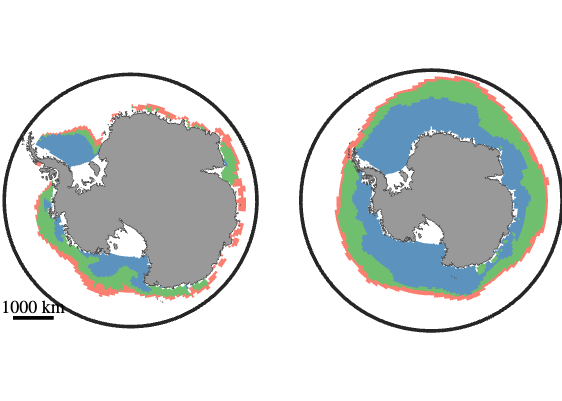

    setm(w, 'grid', 'off');
    setm(w, 'frame', 'on')
    pcolorm(plot_lat,plot_lon,plot_data);
    colormap(Cmap)
    bedmap2('patchgl');
    %outlineashelf('all','color','k');
    %scalebar('color','k','units','km','location','se')
%     scalebar('length',1000,...
%         'units','km',...
%         'color','k','location','sw',...
%         'fontangle','italic')%,'FontSize',font_size)




exportgraphics(f,'worldmap_2019.png', 'ContentType', 'image','Resolution',1000)

conFigure(11,3)
f=figure;

pos1 = [0.0 0.3 0.3 0.3];
subplot('Position',pos1)
plot_lon = lon;
plot_lon(end+1,:) = (lon(1,:));% + lon(end,:))/2;
plot_lat = lat;
plot_lat(end+1,:) = (lat(1,:) + lat(end,:))/2;
plot_data = k(:,:,90);
plot_data(end+1,:) = plot_data(1,:);
landmask = ncread(filename,'tmask');
landmask(end+1,:) = landmask(1,:);


w = worldmap('world');
    axesm eqaazim;
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-52]);
    setm(w, 'maplonlimit', [0,360]);

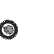

    setm(w, 'grid', 'off');
    setm(w, 'frame', 'on')
    pcolorm(plot_lat,plot_lon,plot_data);
    colormap(Cmap)
    bedmap2('patchgl');


%title('First Subplot')

pos2 = [0.2 0.3 0.3 0.3]

pos2 =     0.2000    0.3000    0.3000    0.3000


subplot('Position',pos2)
plot_lon = lon;
plot_lon(end+1,:) = (lon(1,:));% + lon(end,:))/2;
plot_lat = lat;
plot_lat(end+1,:) = (lat(1,:) + lat(end,:))/2;
plot_data = k(:,:,273);
plot_data(end+1,:) = plot_data(1,:);
landmask = ncread(filename,'tmask');
landmask(end+1,:) = landmask(1,:);

w = worldmap('world');
    axesm eqaazim;
    setm(w, 'Origin', [-90 0 0]);
    setm(w, 'maplatlimit', [-90,-52]);
    setm(w, 'maplonlimit', [0,360]);

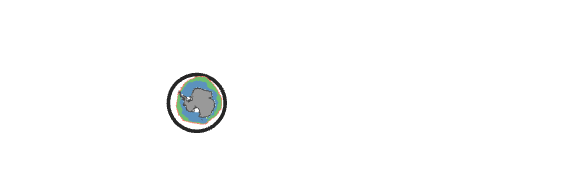

    setm(w, 'grid', 'off');
    setm(w, 'frame', 'on')
    pcolorm(plot_lat,plot_lon,plot_data);
    colormap(Cmap)
    bedmap2('patchgl');
%title('Second Subplot')
exportgraphics(f,'alberto_maps.png', 'ContentType', 'image','BackgroundColor','none')

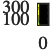

figure()
ax1 = axes;
pcolor(ax1,plot_lat,plot_lon,plot_data)
set(gca, 'Color', 'black'); %sets black background
%colormap(ax1,isnan(plot_data)); %colormap I created which makes the land mask brown
shading flat %get rid of the lines on the figure
hold on
ax2 = axes;
imAlpha = ones(size(plot_data)); 
imAlpha(isnan(plot_data)) = 0; %create NaN mask the size of the overlay
e1 = pcolor(ax2,plot_lat,plot_lon,plot_data);
set(e1,'alphadata',0) %make NaNs transparent. CAUTION: Use "Alphadata" and not "facealpha" or everything
%will be transparent
%colormap(ax2,cm_overlay) %colormap I created for the overlay
shading flat
hold on
set(gca, 'Color', 'none'); %IMPORTANT: set the second background as transparent otherwise it covers the land mask
axis tight

tarea = ncread(filename,'tarea');

for i = 1:365
    for class = 0:2
        k_day = k(:,:,i);
        idx = k_day == class;
        areas(class+1,i) = sum(sum(tarea(idx)));
    end
end

t1 = datetime(2011,1,1,0,0,0);
t2 = datetime(2011,12,31,0,0,0);
t = t1:t2

t = 1×365 datetime array
   01-Jan-2011   02-Jan-2011   03-Jan-2011   04-Jan-2011   05-Jan-2011   06-Jan-2011   07-Jan-2011   08-Jan-2011   09-Jan-2011   10-Jan-2011   11-Jan-2011   12-Jan-2011   13-Jan-2011   14-Jan-2011   15-Jan-2011   16-Jan-2011   17-Jan-2011   18-Jan-2011   19-Jan-2011   20-Jan-2011   21-Jan-2011   22-Jan-2011   23-Jan-2011   24-Jan-2011   25-Jan-2011   26-Jan-2011   27-Jan-2011   28-Jan-2011   29-Jan-2011   30-Jan-2011   31-Jan-2011   01-Feb-2011   02-Feb-2011   03-Feb-2011   04-Feb-2011   05-Feb-2011   06-Feb-2011   07-Feb-2011   08-Feb-2011   09-Feb-2011   10-Feb-2011   11-Feb-2011   12-Feb-2011   13-Feb-2011   14-Feb-2011   15-Feb-2011   16-Feb-2011   17-Feb-2011   18-Feb-2011   19-Feb-2011   20-Feb-2011   21-Feb-2011   22-Feb-2011   23-Feb-2011   24-Feb-2011   25-Feb-2011   26-Feb-2011   27-Feb-2011   28-Feb-2011   01-Mar-2011   02-Mar-2011   03-Mar-2011   04-Mar-2011   05-Mar-2011   06-Mar-2011   07-Mar-2011   08-Mar-2011   09-Mar-2011   10-Mar-2011   11-Mar

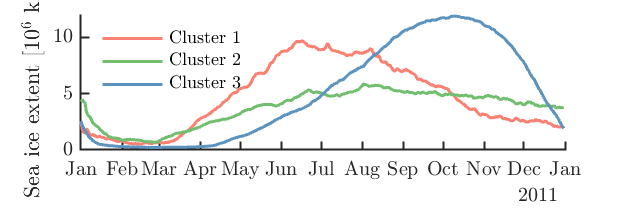

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0 (commit 806c97d99f87f8a1e99a7c54e853c25c82aac301).
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


conFigure(11,3)
f = figure;
for i = 1:3
    plot(t,areas(i,:)./(10^12),'color',Cmap(i,:),'linewidth',1.5)
    hold on
end
%Returns handles to the patch and line objects
%chi=get(gca, 'Children');
%Reverse the stacking order so that the patch overlays the line
%set(gca, 'Children',flipud(chi))

%colormap(Cmap)
ylabel('Sea ice extent [$10^6$ km$^2$]')
legend('Cluster 1','Cluster 2','Cluster 3','location','northwest');
legend boxoff  
set(gca,'box','off')

exportgraphics(f,'cluster-SIE.pdf', 'ContentType', 'vector')
addpath /Users/noahday/Documents/MATLAB/matlab2tikz/src/
matlab2tikz('cluster-SIA.tex', 'standalone', true);

ncdisp('/Users/noahday/GitHub/sea-ice-classification/kmean_2013.nc')

Source:
           /Users/noahday/GitHub/sea-ice-classification/kmean_2013.nc
Format:
           netcdf4
Global Attributes:
           creation_date = '2023-04-07'
           conventions   = ''
           title         = 'k-means clusters for CICE-WIM standalone 1-degree data'
           source        = ', '
           comment       = ''
           author        = 'Noah Day'
           email         = 'noah.day@adelaide.edu.au'
Dimensions:
           time = 365   (UNLIMITED)
           nj   = 300
           ni   = 360
Variables:
    k          
           Size:       360x300x365
           Dimensions: ni,nj,time
           Datatype:   double
           Attributes:
                       _FillValue  = -200000000
                       long_name   = 'k-means_clusters'
                       units       = 'cluster number'
                       coordinates = 'LAT LON'
    aice       
           Size:       360x300x365
           Dimensions: ni,nj,time
           Datatype:   double
       

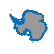


% close all
% figure
% bedmap2('patchgl');
% outlineashelf('all','linewidth',1);

% 
% exportgraphics(f,'ice-shelves.pdf', 'ContentType', 'vector')

Error using exportgraphics
First parameter must specify the axes or
chart object.

%   bedmap2('gl','xy') 
%   bedmap2('coast','xy','color','m','linewidth',2)
% antmap('color','red',...       % in red
%     'linewidth',2,...       % kinda thick
%     'linestyle',':',...     % and dotted
%     'oceancolor',rgb('ocean blue')) % and sets ocean color.
% patchm(lat(1,:),lon(:,1),[.5 .5 .5]) % plot gray continent
       % title(dirdates(file_number,:),'Color','black','FontSize',font_size+5)
 
        %cb.Location = 'eastoutside';
        
        %cb.AxisLocation = 'in';
